# Proyecto Global Integrador - Análisis y Control de Accionamiento PMSM

Este script acompaña el informe técnico, estructurado desde la definición del modelo físico real (No Lineal), pasando por su análisis (LTI), hasta llegar al diseño y validación de las leyes de control por etapas.

## Inicializacion del Sistema

clear; clc; close all;

run("init_sistema_completo.m")

--------------------------------------------------
Iniciando carga de parámetros del sistema acoplado...
--------------------------------------------------
Cargando: params_subsistema_mecanico.m ...
Cargando: params_subsistema_electromagnetico.m ...
Cargando: params_subsistema_termico.m ...
--------------------------------------------------
¡ÉXITO! Todos los parámetros han sido cargados.
--------------------------------------------------



% Requerimientos de diseño
p_c = -5000;    % Ubicacion deseada del polo de corriente [rad/s]

## 1. Modelo Global No Lineal

disp('--- 1. Definición Simbólica del Estado Global No Lineal ---');

--- 1. Definición Simbólica del Estado Global No Lineal ---



% Variables de estado y entradas
syms x1 x2 x3 x4 x5 x6 real
syms u1 u2 u3 u4 u5 real
syms J_eq_sym b_eq_sym K_t_sym K_rel_sym g_sym k_l_sym r_sym real positive
syms L_q_sym L_d_sym L_0s_sym R_s_sym alpha_Cu_sym T_REF_sym P_p_sym lambda_m_sym real positive
syms C_ts_sym R_ts_amb_sym real positive

% Dependencia paramétrica térmica de la Resistencia
R_s_T = R_s_sym * (1 + alpha_Cu_sym * (x6 - T_REF_sym));

% Ecuaciones Diferenciales Ordinarias (ODE)
dx1 = x2;
dx2 = (1/J_eq_sym) * (K_t_sym*x3 + K_rel_sym*x4*x3 - b_eq_sym*x2 - (g_sym*k_l_sym/r_sym)*sin(x1/r_sym) - u4/r_sym);
dx3 = (1/L_q_sym)  * (u1 - R_s_T*x3 - (lambda_m_sym + L_d_sym*x4)*P_p_sym*x2);
dx4 = (1/L_d_sym)  * (u2 - R_s_T*x4 + L_q_sym*x3*P_p_sym*x2);
dx5 = (1/L_0s_sym) * (u3 - R_s_T*x5);
dx6 = (1/C_ts_sym) * ((3/2)*R_s_T*(x3^2 + x4^2 + 2*x5^2) - (x6 - u5)/R_ts_amb_sym);

F_NL = [dx1; dx2; dx3; dx4; dx5; dx6];
disp('Vector de derivadas del estado f(x,u) [Modelo Completo]:')

Vector de derivadas del estado f(x,u) [Modelo Completo]:


disp(F_NL)

$$\begin{array}{l} \left(\begin{array}{c} x_{2}\\ -\frac{b_{\mathrm{eq},\mathrm{sym}}\,x_{2}-K_{t,\mathrm{sym}}\,x_{3}+\frac{u_{4}}{r_{\mathrm{sym}}}-K_{\mathrm{rel},\mathrm{sym}}\,x_{3}\,x_{4}+\frac{g_{\mathrm{sym}}\,k_{l,\mathrm{sym}}\,\sin\left(\frac{x_{1}}{r_{\mathrm{sym}}}\right)}{r_{\mathrm{sym}}}}{J_{\mathrm{eq},\mathrm{sym}}}\\ \frac{u_{1}-P_{p,\mathrm{sym}}\,x_{2}\,\left(\lambda_{m,\mathrm{sym}}+L_{d,\mathrm{sym}}\,x_{4}\right)+R_{s,\mathrm{sym}}\,x_{3}\,\sigma_{1}}{L_{q,\mathrm{sym}}}\\ \frac{u_{2}+R_{s,\mathrm{sym}}\,x_{4}\,\sigma_{1}+L_{q,\mathrm{sym}}\,P_{p,\mathrm{sym}}\,x_{2}\,x_{3}}{L_{d,\mathrm{sym}}}\\ \frac{u_{3}+R_{s,\mathrm{sym}}\,x_{5}\,\sigma_{1}}{L_{\mathrm{0s},\mathrm{sym}}}\\ \frac{\frac{u_{5}-x_{6}}{R_{\mathrm{ts},\mathrm{amb},\mathrm{sym}}}-\frac{3\,R_{s,\mathrm{sym}}\,\sigma_{1}\,\left({x_{3}}^{2}+{x_{4}}^{2}+2\,{x_{5}}^{2}\right)}{2}}{C_{\mathrm{ts},\mathrm{sym}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\alpha_{\mathrm{Cu},\mathrm{sym}}\,\left(T_{\mathrm{REF},\mathrm{sym}}-x_{6}\right)-1 \end{array}$$

## 2. Análisis del Modelo LTI

### 2.a) Validación Simbólica del Polinomio Característico y Funciones de Transferencia

disp('--- 2. Validación Simbólica del Polinomio Característico y FT ---');

--- 2. Validación Simbólica del Polinomio Característico y FT ---



% Definición de variables simbólicas (reales y positivas)
syms s K_v_sym real positive

% Matriz del sistema M(s) (Subsistema electromagnético)
M_s = [ s,                  -1,               0;
        0,     J_eq_sym*s + b_eq_sym,            -K_t_sym;
        0,               K_v_sym,  L_q_sym*s + R_s_sym ];

% Matriz de entrada B_in asociada al vector U(s) = [V_qs; T_l]'
B_in = [   0,    0;
           0, -1/r_sym;
           1,    0 ];

% Matriz de transferencia del sistema G_matriz = inv(M_s) * B_in
disp('Matriz de Transferencia Completa del Sistema:')

Matriz de Transferencia Completa del Sistema:


G_matriz = simplify(M_s \ B_in)

$$G\_matriz = \begin{array}{l} \left(\begin{array}{cc} \frac{K_{t,\mathrm{sym}}}{s\,\sigma_{1}} & -\frac{R_{s,\mathrm{sym}}+L_{q,\mathrm{sym}}\,s}{r_{\mathrm{sym}}\,s\,\sigma_{1}}\\ \frac{K_{t,\mathrm{sym}}}{\sigma_{1}} & -\frac{R_{s,\mathrm{sym}}+L_{q,\mathrm{sym}}\,s}{r_{\mathrm{sym}}\,\sigma_{1}}\\ \frac{b_{\mathrm{eq},\mathrm{sym}}+J_{\mathrm{eq},\mathrm{sym}}\,s}{\sigma_{1}} & \frac{K_{v,\mathrm{sym}}}{r_{\mathrm{sym}}\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R_{s,\mathrm{sym}}\,b_{\mathrm{eq},\mathrm{sym}}+K_{t,\mathrm{sym}}\,K_{v,\mathrm{sym}}+J_{\mathrm{eq},\mathrm{sym}}\,R_{s,\mathrm{sym}}\,s+L_{q,\mathrm{sym}}\,b_{\mathrm{eq},\mathrm{sym}}\,s+J_{\mathrm{eq},\mathrm{sym}}\,L_{q,\mathrm{sym}}\,s^{2} \end{array}$$


% Aislamiento de las plantas individuales
G_v_raw = G_matriz(1,1); % Canal Tensión -> Posición
G_d_raw = G_matriz(1,2); % Canal Torque -> Posición

disp('Función de Transferencia Principal G_v(s) [V_qs -> Theta_m]:')

Función de Transferencia Principal G_v(s) [V_qs -> Theta_m]:


G_v = collect(G_v_raw, s)

$$G\_v = \frac{K_{t,\mathrm{sym}}}{\left(J_{\mathrm{eq},\mathrm{sym}}\,L_{q,\mathrm{sym}}\right)\,s^{3}+\left(L_{q,\mathrm{sym}}\,b_{\mathrm{eq},\mathrm{sym}}+J_{\mathrm{eq},\mathrm{sym}}\,R_{s,\mathrm{sym}}\right)\,s^{2}+\left(R_{s,\mathrm{sym}}\,b_{\mathrm{eq},\mathrm{sym}}+K_{t,\mathrm{sym}}\,K_{v,\mathrm{sym}}\right)\,s}$$


disp('Función de Transferencia de Perturbación G_d(s) [T_l -> Theta_m]:')

Función de Transferencia de Perturbación G_d(s) [T_l -> Theta_m]:


G_d = collect(G_d_raw, s)

$$G\_d = \frac{\left(-L_{q,\mathrm{sym}}\right)\,s-R_{s,\mathrm{sym}}}{\left(J_{\mathrm{eq},\mathrm{sym}}\,L_{q,\mathrm{sym}}\,r_{\mathrm{sym}}\right)\,s^{3}+\left(J_{\mathrm{eq},\mathrm{sym}}\,R_{s,\mathrm{sym}}\,r_{\mathrm{sym}}+L_{q,\mathrm{sym}}\,b_{\mathrm{eq},\mathrm{sym}}\,r_{\mathrm{sym}}\right)\,s^{2}+\left(K_{t,\mathrm{sym}}\,K_{v,\mathrm{sym}}\,r_{\mathrm{sym}}+R_{s,\mathrm{sym}}\,b_{\mathrm{eq},\mathrm{sym}}\,r_{\mathrm{sym}}\right)\,s}$$


% Extracción del Polinomio Característico
[~, Dinominador_Comun] = numden(G_v_raw);
disp('Polinomio Característico del Motor Delta(s):')

Polinomio Característico del Motor Delta(s):


Delta_s = collect(Dinominador_Comun, s)

$$Delta\_s = \left(J_{\mathrm{eq},\mathrm{sym}}\,L_{q,\mathrm{sym}}\right)\,s^{3}+\left(L_{q,\mathrm{sym}}\,b_{\mathrm{eq},\mathrm{sym}}+J_{\mathrm{eq},\mathrm{sym}}\,R_{s,\mathrm{sym}}\right)\,s^{2}+\left(R_{s,\mathrm{sym}}\,b_{\mathrm{eq},\mathrm{sym}}+K_{t,\mathrm{sym}}\,K_{v,\mathrm{sym}}\right)\,s$$


% Separación del polo integrador (s=0)
Delta_em_s = simplify(Delta_s / s);
Delta_em_exp = collect(expand(Delta_em_s), s);

% Extraemos los coeficientes del polinomio de segundo orden (A*s^2 + B*s + C = 0
coeficientes = coeffs(Delta_em_exp, s);
C_sym = coeficientes(1); 
B_sym = coeficientes(2); 
A_sym = coeficientes(3);

% Cálculo simbólico de la frecuencia natural y amortiguamiento
wn_simbolico = sqrt(simplify(C_sym / A_sym));
zeta_simbolico = simplify((B_sym / A_sym) / (2 * wn_simbolico));

disp('--- Parámetros del Modo Electromecánico ---');

--- Parámetros del Modo Electromecánico ---


disp('Frecuencia natural no amortiguada (\omega_{n,em}):')

Frecuencia natural no amortiguada (\omega_{n,em}):


wn_em_sym = wn_simbolico

$$wn\_em\_sym = \frac{\sqrt{R_{s,\mathrm{sym}}\,b_{\mathrm{eq},\mathrm{sym}}+K_{t,\mathrm{sym}}\,K_{v,\mathrm{sym}}}}{\sqrt{J_{\mathrm{eq},\mathrm{sym}}}\,\sqrt{L_{q,\mathrm{sym}}}}$$

disp('Factor de amortiguamiento (\zeta_{em}):')

Factor de amortiguamiento (\zeta_{em}):


zeta_em_sym = zeta_simbolico

$$zeta\_em\_sym = \frac{L_{q,\mathrm{sym}}\,b_{\mathrm{eq},\mathrm{sym}}+J_{\mathrm{eq},\mathrm{sym}}\,R_{s,\mathrm{sym}}}{2\,\sqrt{J_{\mathrm{eq},\mathrm{sym}}}\,\sqrt{L_{q,\mathrm{sym}}}\,\sqrt{R_{s,\mathrm{sym}}\,b_{\mathrm{eq},\mathrm{sym}}+K_{t,\mathrm{sym}}\,K_{v,\mathrm{sym}}}}$$

### 2.b) Analisis del Caso Nominal (Valores numéricos e Identificacion)

% Constantes electromagneticas derivadas (asumiendo I_ds = 0)
K_t = (3/2) * Pp * lambda_m;
K_v = Pp * lambda_m;

% Cálculo de Parámetros Dinámicos Nominales
wn_nom = sqrt((Rs_REF * beq_nom + K_t * K_v) / (Jeq_nom * L_q));
zeta_nom = (L_q * beq_nom + Rs_REF * Jeq_nom) / (2 * sqrt(Jeq_nom * L_q * (Rs_REF * beq_nom + K_t * K_v)));

% Identificación de Autovalores (Polos)
% Modo Integrador (Cinematico)
p1_nom = 0;

% Modos Electromecanicos Conjugados
sigma_nom = zeta_nom * wn_nom;
wd_nom = wn_nom * sqrt(1 - zeta_nom^2);
p23_nom = [-sigma_nom + 1i*wd_nom; -sigma_nom - 1i*wd_nom];

% Modos Residuales Inobservables
pd_nom = -Rs_REF / L_d;
pT_nom = -1 / (Rts_amb * Cts);

% Identificacion de Ceros
zd_nom = -Rs_REF / L_q;

% --- IMPRESIÓN DE RESULTADOS (Formato Tabla Profesional) ---
disp('================================================================');

disp('POLOS, CEROS Y MODOS DE OSCILACIÓN (CASO NOMINAL)       ');

POLOS, CEROS Y MODOS DE OSCILACIÓN (CASO NOMINAL)       


disp('================================================================');

fprintf('\n--- 1. Subsistema Cinemático (Integrador) ---\n');


--- 1. Subsistema Cinemático (Integrador) ---


fprintf('Polo p1        = %0.2f\n', p1_nom);

Polo p1        = 0.00


fprintf('Efecto         : Posición libre sin resorte de retorno.\n');

Efecto         : Posición libre sin resorte de retorno.



fprintf('\n--- 2. Subsistema Electromecánico (Dominante) ---\n');


--- 2. Subsistema Electromecánico (Dominante) ---


fprintf('Polos p2,3     = %0.2f ± j%0.2f rad/s\n', real(p23_nom(1)), imag(p23_nom(1)));

Polos p2,3     = -88.49 ± j149.94 rad/s


fprintf('Frec. Natural  : wn_nom = %0.2f rad/s (%0.2f Hz)\n', wn_nom, wn_nom/(2*pi));

Frec. Natural  : wn_nom = 174.10 rad/s (27.71 Hz)


fprintf('Amortiguamiento: zeta   = %0.4f (Subamortiguado)\n', zeta_nom);

Amortiguamiento: zeta   = 0.5082 (Subamortiguado)


fprintf('Cte. de Tiempo : tau_em = %0.4f s (Decaimiento de la envolvente)\n', 1/sigma_nom);

Cte. de Tiempo : tau_em = 0.0113 s (Decaimiento de la envolvente)



fprintf('\n--- 3. Subsistemas Desacoplados (Inobservables desde theta_m) ---\n');


--- 3. Subsistemas Desacoplados (Inobservables desde theta_m) ---


fprintf('Polo eje d (pd) = %0.2f rad/s  --> tau_d = %0.4f s\n', pd_nom, -1/pd_nom);

Polo eje d (pd) = -154.55 rad/s  --> tau_d = 0.0065 s


fprintf('Polo Térm. (pT) = %0.4f rad/s  --> tau_T = %0.2f s\n', pT_nom, -1/pT_nom);

Polo Térm. (pT) = -0.0083 rad/s  --> tau_T = 120.00 s



fprintf('\n--- 4. Ceros de Transmisión ---\n');


--- 4. Ceros de Transmisión ---


fprintf('Cero Perturb.  : z_d = %0.2f rad/s\n', zd_nom);

Cero Perturb.  : z_d = -175.86 rad/s


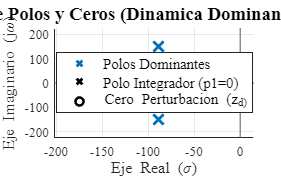


% Instanciamos la clase gráfica profesional
plotter_nom = SignalPlotter("docs/img/");

polesList_nom = {p23_nom};
[fig_pz, ax_pz] = plotter_nom.plotPoleSweep(polesList_nom, 100, '', ...
    'Title', 'Mapa de Polos y Ceros (Dinamica Dominante Nominal)');

hold(ax_pz, 'on');

% Polo en el Origen
scatter(ax_pz, 0, 0, 120, 'x', 'MarkerEdgeColor', 'k', 'LineWidth', 2, ...
    'DisplayName', 'Polo Integrador (p1=0)');

% Cero de Perturbacion
scatter(ax_pz, real(zd_nom), imag(zd_nom), 120, 'o', 'MarkerEdgeColor', 'k', 'LineWidth', 2, ...
    'DisplayName', 'Cero Perturbacion (z_d)');

% Llamamos a la leyenda al final
legend(ax_pz, 'Location', 'best', 'FontName', plotter_nom.FontFamily, 'FontSize', plotter_nom.FontSizeLegend);

% --- AJUSTES DE ENCUADRE DINÁMICO ---
% Límite Y: Mantiene la proporción respecto a la frecuencia amortiguada
ylim(ax_pz, [-(wd_nom*1.5), (wd_nom*1.5)]); 

% Límite X: Busca el valor más negativo (el cero o los polos) y le da 15% de margen
limite_izq = min([real(p23_nom(1)), zd_nom]) * 1.15; 
limite_der = 15; % Margen fijo a la derecha para que el polo en el origen no quede pegado al borde

xlim(ax_pz, [limite_izq, limite_der]);   

hold(ax_pz, 'off');


% plotter_nom.export(fig_pz, 'mapa_pz_nominal.pdf');

% --- IMPRESIÓN DE RESULTADOS (Formato Tabla Profesional) ---
disp('================================================================');

disp('   2.a) POLOS, CEROS Y MODOS DE OSCILACIÓN (CASO NOMINAL)       ');

   2.a) POLOS, CEROS Y MODOS DE OSCILACIÓN (CASO NOMINAL)       


disp('================================================================');

fprintf('\n--- 1. Subsistema Cinemático (Integrador) ---\n');


--- 1. Subsistema Cinemático (Integrador) ---


fprintf('Polo p1        = %0.2f\n', p1_nom);

Polo p1        = 0.00


fprintf('Efecto         : Posición libre sin resorte de retorno.\n');

Efecto         : Posición libre sin resorte de retorno.



fprintf('\n--- 2. Subsistema Electromecánico (Dominante) ---\n');


--- 2. Subsistema Electromecánico (Dominante) ---


fprintf('Polos p2,3     = %0.2f ± j%0.2f rad/s\n', real(p23_nom(1)), imag(p23_nom(1)));

Polos p2,3     = -88.49 ± j149.94 rad/s


fprintf('Frec. Natural  : wn_nom = %0.2f rad/s (%0.2f Hz)\n', wn_nom, wn_nom/(2*pi));

Frec. Natural  : wn_nom = 174.10 rad/s (27.71 Hz)


fprintf('Amortiguamiento: zeta   = %0.4f (Subamortiguado)\n', zeta_nom);

Amortiguamiento: zeta   = 0.5082 (Subamortiguado)


fprintf('Cte. de Tiempo : tau_em = %0.4f s (Decaimiento de la envolvente)\n', 1/sigma_nom);

Cte. de Tiempo : tau_em = 0.0113 s (Decaimiento de la envolvente)



fprintf('\n--- 3. Subsistemas Desacoplados (Inobservables desde theta_m) ---\n');


--- 3. Subsistemas Desacoplados (Inobservables desde theta_m) ---


fprintf('Polo eje d (pd) = %0.2f rad/s  --> tau_d = %0.4f s\n', pd_nom, -1/pd_nom);

Polo eje d (pd) = -154.55 rad/s  --> tau_d = 0.0065 s


fprintf('Polo Térm. (pT) = %0.4f rad/s  --> tau_T = %0.2f s\n', pT_nom, -1/pT_nom);

Polo Térm. (pT) = -0.0083 rad/s  --> tau_T = 120.00 s



fprintf('\n--- 4. Ceros de Transmisión ---\n');


--- 4. Ceros de Transmisión ---


fprintf('Cero Perturb.  : z_d = %0.2f rad/s\n', zd_nom);

Cero Perturb.  : z_d = -175.86 rad/s


fprintf('Efecto         : Adelanto de fase local ante torque de carga.\n');

Efecto         : Adelanto de fase local ante torque de carga.


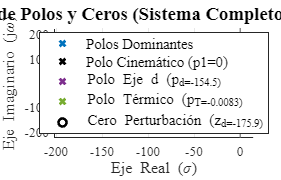


% Instanciamos la clase gráfica profesional
plotter_nom = SignalPlotter("docs/img/");

% Pasamos los polos dominantes al método principal para mantener el formato
polesList_nom = {p23_nom};
[fig_pz, ax_pz] = plotter_nom.plotPoleSweep(polesList_nom, 100, '', ...
    'Title', 'Mapa de Polos y Ceros (Sistema Completo Nominal)');

hold(ax_pz, 'on');

% Polo en el Origen (Cinemático)
scatter(ax_pz, p1_nom, 0, 120, 'x', 'MarkerEdgeColor', 'k', 'LineWidth', 2, ...
    'DisplayName', 'Polo Cinemático (p1=0)');

% Polo del eje d (Eléctrico residual)
scatter(ax_pz, pd_nom, 0, 120, 'x', 'MarkerEdgeColor', plotter_nom.ColorPalette{4}, 'LineWidth', 2, ...
    'DisplayName', sprintf('Polo Eje d (p_d=%.1f)', pd_nom));

% Polo Térmico (Estator)
scatter(ax_pz, pT_nom, 0, 120, 'x', 'MarkerEdgeColor', plotter_nom.ColorPalette{5}, 'LineWidth', 2, ...
    'DisplayName', sprintf('Polo Térmico (p_T=%.4f)', pT_nom));

% Cero de Perturbación
scatter(ax_pz, real(zd_nom), imag(zd_nom), 120, 'o', 'MarkerEdgeColor', 'k', 'LineWidth', 2, ...
    'DisplayName', sprintf('Cero Perturbación (z_d=%.1f)', zd_nom));

% Llamamos a la leyenda al final
legend(ax_pz, 'Location', 'best', 'FontName', plotter_nom.FontFamily, 'FontSize', plotter_nom.FontSizeLegend);

% --- AJUSTES DE ENCUADRE DINÁMICO ---
% Límite Y: Mantiene la proporción respecto a la frecuencia amortiguada dominante
ylim(ax_pz, [-(wd_nom*1.5), (wd_nom*1.5)]); 

% Límite X: Busca el valor más negativo evaluando TODOS los polos y ceros
limite_izq = min([real(p23_nom(1)), zd_nom, pd_nom, pT_nom, p1_nom]) * 1.15; 
limite_der = 15; % Margen fijo a la derecha para que el polo en el origen no quede pegado al borde

xlim(ax_pz, [limite_izq, limite_der]);   

hold(ax_pz, 'off');

## 3. Análisis de Robustez y Sensibilidad (Migración de Polos)

#### 3.a) Variación de masa de Carga Útil (m_l)

disp('--- Análisis de Sensibilidad: Masa de Carga (m_l) ---');

--- Análisis de Sensibilidad: Masa de Carga (m_l) ---



num_steps = 15; % Mayor resolución para ver la curva suave
ml_sweep = linspace(ml_min, ml_max, num_steps);

% Inicialización de celdas y vectores
polesList_ml = cell(num_steps, 1);
wn_ml_array = zeros(num_steps, 1);
zeta_ml_array = zeros(num_steps, 1);

for i = 1:num_steps
    % 1. Extraemos parámetro actual
    ml_i = ml_sweep(i);
    
    % 2. Propagación hacia Inercia Equivalente (Jeq)
    Jl_i = (m*Lcm^2 + Jcm) + ml_i*Ll^2;
    Jeq_i = Jm + Jl_i/r^2;
    
    % Mantenemos fricción y resistencia nominales
    beq_i = beq_nom;
    Rs_i = Rs_REF;
    
    % 3. Cálculo de la dinámica dominante
    wn_i   = sqrt((Rs_i * beq_i + K_t * K_v) / (Jeq_i * L_q));
    zeta_i = (L_q * beq_i + Rs_i * Jeq_i) / ...
             (2 * sqrt(Jeq_i * L_q * (Rs_i * beq_i + K_t * K_v)));
    
    sigma_i = zeta_i * wn_i;
    wd_i    = wn_i * sqrt(1 - zeta_i^2);
    
    % 4. Almacenamiento
    polesList_ml{i} = [-sigma_i + 1i*wd_i; -sigma_i - 1i*wd_i];
    wn_ml_array(i) = wn_i;
    zeta_ml_array(i) = zeta_i;
end

% --- RESULTADOS EXTREMOS EN CONSOLA ---
idx_mid = ceil(num_steps / 2);
fprintf('Condición Mínima (m_l = %.2f kg): wn = %6.2f rad/s, zeta = %.4f\n', ml_sweep(1), wn_ml_array(1), zeta_ml_array(1));

Condición Mínima (m_l = 0.00 kg): wn = 174.10 rad/s, zeta = 0.5082


fprintf('Condición Media  (m_l = %.2f kg): wn = %6.2f rad/s, zeta = %.4f\n', ml_sweep(idx_mid), wn_ml_array(idx_mid), zeta_ml_array(idx_mid));

Condición Media  (m_l = 0.75 kg): wn = 135.21 rad/s, zeta = 0.6528


fprintf('Condición Máxima (m_l = %.2f kg): wn = %6.2f rad/s, zeta = %.4f\n', ml_sweep(end), wn_ml_array(end), zeta_ml_array(end));

Condición Máxima (m_l = 1.50 kg): wn = 114.40 rad/s, zeta = 0.7707


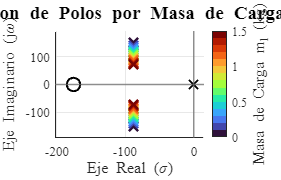


% =========================================================================
% --- DIAGRAMA DE LUGAR DE RAÍCES: VARIACIÓN m_l ---
% =========================================================================
plotter_ml = SignalPlotter("docs/img/");
etiqueta_colorbar_ml = 'Masa de Carga m_{l} (kg)'; 

[fig_ml, ax_ml] = plotter_ml.plotPoleSweep(...
    polesList_ml, ...
    ml_sweep, ...
    etiqueta_colorbar_ml, ...
    'Title', 'Migracion de Polos por Masa de Carga (m_l)');

hold(ax_ml, 'on');

% Marcadores de Referencia Fijos
scatter(ax_ml, p1_nom, 0, 100, 'x', 'MarkerEdgeColor', 'k', 'LineWidth', 1.5, 'HandleVisibility', 'off');
scatter(ax_ml, real(zd_nom), imag(zd_nom), 100, 'o', 'MarkerEdgeColor', 'k', 'LineWidth', 1.5, 'HandleVisibility', 'off');

% Ajuste de límites estandarizado
xlim_min_sweep = min([real(polesList_ml{1}(1)), zd_nom]) * 1.15;
xlim(ax_ml, [xlim_min_sweep, 15]);
ylim(ax_ml, [-(wn_ml_array(1) * 1.1), (wn_ml_array(1) * 1.1)]);   

hold(ax_ml, 'off');


%plotter_ml.export(fig_ml, 'mapa_pz_migracion_ml.pdf');

### 3.b) Migracion de Polos: Variacion de Friccion Viscosa

disp('--- Análisis de Sensibilidad: Fricción Viscosa de Carga (b_l) ---');

--- Análisis de Sensibilidad: Fricción Viscosa de Carga (b_l) ---


bl_sweep = linspace(bl_min, bl_max, num_steps);

polesList_bl = cell(num_steps, 1);
wn_bl_array = zeros(num_steps, 1);
zeta_bl_array = zeros(num_steps, 1);

for i = 1:num_steps
    % 1. Extraemos parámetro actual
    bl_i = bl_sweep(i);
    
    % 2. Propagación hacia Fricción Equivalente (beq)
    beq_i = bm + bl_i/r^2;
    
    % Mantenemos inercia y resistencia nominales
    Jeq_i = Jeq_nom;
    Rs_i = Rs_REF;
    
    % 3. Cálculo de la dinámica dominante
    wn_i   = sqrt((Rs_i * beq_i + K_t * K_v) / (Jeq_i * L_q));
    zeta_i = (L_q * beq_i + Rs_i * Jeq_i) / ...
             (2 * sqrt(Jeq_i * L_q * (Rs_i * beq_i + K_t * K_v)));
    
    sigma_i = zeta_i * wn_i;
    wd_i    = wn_i * sqrt(1 - zeta_i^2);
    
    % 4. Almacenamiento
    polesList_bl{i} = [-sigma_i + 1i*wd_i; -sigma_i - 1i*wd_i];
    wn_bl_array(i) = wn_i;
    zeta_bl_array(i) = zeta_i;
end

% --- RESULTADOS EN CONSOLA (Mínimo, Nominal, Máximo) ---
fprintf('Condición Mínima  (b_l = %5.3f): wn = %6.2f rad/s, zeta = %.4f\n', bl_sweep(1), wn_bl_array(1), zeta_bl_array(1));

Condición Mínima  (b_l = 0.070): wn = 174.05 rad/s, zeta = 0.5081


fprintf('Condición Nominal (b_l = %5.3f): wn = %6.2f rad/s, zeta = %.4f\n', bl_sweep(idx_mid), wn_bl_array(idx_mid), zeta_bl_array(idx_mid));

Condición Nominal (b_l = 0.100): wn = 174.10 rad/s, zeta = 0.5082


fprintf('Condición Máxima  (b_l = %5.3f): wn = %6.2f rad/s, zeta = %.4f\n', bl_sweep(end), wn_bl_array(end), zeta_bl_array(end));

Condición Máxima  (b_l = 0.130): wn = 174.16 rad/s, zeta = 0.5084


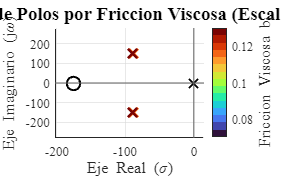


% =========================================================================
% --- DIAGRAMA 1: ESCALA GLOBAL (Consistencia visual) ---
% =========================================================================
plotter_bl = SignalPlotter("docs/img/");
etiqueta_colorbar_bl = 'Friccion Viscosa b_l'; 

[fig_bl_global, ax_bl_global] = plotter_bl.plotPoleSweep(...
    polesList_bl, bl_sweep, etiqueta_colorbar_bl, ...
    'Title', 'Migracion de Polos por Friccion Viscosa (Escala Global)');

hold(ax_bl_global, 'on');
scatter(ax_bl_global, p1_nom, 0, 100, 'x', 'MarkerEdgeColor', 'k', 'LineWidth', 1.5, 'HandleVisibility', 'off');
scatter(ax_bl_global, real(zd_nom), imag(zd_nom), 100, 'o', 'MarkerEdgeColor', 'k', 'LineWidth', 1.5, 'HandleVisibility', 'off');

% Misma escala que en m_l
xlim(ax_bl_global, [xlim_min_sweep, 15]);
ylim(ax_bl_global, [-(wn_nom * 1.6), (wn_nom * 1.6)]);   
hold(ax_bl_global, 'off');

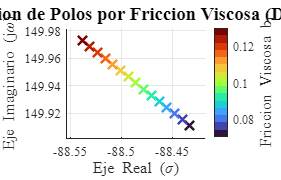


% =========================================================================
% --- DIAGRAMA 2: ZOOM EN EL POLO SUPERIOR ---
% =========================================================================
% Extraemos solo la parte real e imaginaria del polo superior (índice 1)
partes_reales = cellfun(@(p) real(p(1)), polesList_bl);
partes_imags  = cellfun(@(p) imag(p(1)), polesList_bl);

% Calculamos márgenes ajustados (10% de la máxima variación)
margen_real = abs(max(partes_reales) - min(partes_reales)) * 0.15;
margen_imag = abs(max(partes_imags) - min(partes_imags)) * 0.15;
if margen_real == 0, margen_real = 0.01; end % Evita errores si el polo no se mueve en absoluto
if margen_imag == 0, margen_imag = 0.01; end

[fig_bl_zoom, ax_bl_zoom] = plotter_bl.plotPoleSweep(...
    polesList_bl, bl_sweep, etiqueta_colorbar_bl, ...
    'Title', 'Migracion de Polos por Friccion Viscosa (Detalle)');

% Aplicamos el encuadre milimétrico sobre la trayectoria del polo
xlim(ax_bl_zoom, [min(partes_reales) - margen_real, max(partes_reales) + margen_real]);
ylim(ax_bl_zoom, [min(partes_imags) - margen_imag, max(partes_imags) + margen_imag]);





%plotter_bl.export(fig_bl_global, 'mapa_pz_migracion_bl_global.pdf');
%plotter_bl.export(fig_bl_zoom, 'mapa_pz_migracion_bl_zoom.pdf');

### 3.c) MIGRACIÓN DE POLOS Y CEROS: VARIACIÓN TÉRMICA DE ESTATOR (T_s)

disp('--- Análisis de Sensibilidad: Temperatura del Estator (T_s) ---');

--- Análisis de Sensibilidad: Temperatura del Estator (T_s) ---



% Rango de variación térmica
Ts_min = Ts_REF;         % 20 °C (Motor en frío)
Ts_max = 115.0;          % 115 °C (Límite operativo máximo)

num_steps = 15; 
Ts_sweep = linspace(Ts_min, Ts_max, num_steps);

polesList_Ts  = cell(num_steps, 1);
zd_Ts_array   = zeros(num_steps, 1);
wn_Ts_array   = zeros(num_steps, 1);
zeta_Ts_array = zeros(num_steps, 1);

for i = 1:num_steps
    Ts_i = Ts_sweep(i);
    Rs_i = Rs_REF * (1 + alpha_Cu * (Ts_i - Ts_REF));
    
    % Mantenemos inercia y fricción nominales
    Jeq_i = Jeq_nom;
    beq_i = beq_nom;
    
    % Cálculo de la dinámica dominante
    wn_i   = sqrt((Rs_i * beq_i + K_t * K_v) / (Jeq_i * L_q));
    zeta_i = (L_q * beq_i + Rs_i * Jeq_i) / ...
             (2 * sqrt(Jeq_i * L_q * (Rs_i * beq_i + K_t * K_v)));
    
    sigma_i = zeta_i * wn_i;
    wd_i    = wn_i * sqrt(1 - zeta_i^2);
    
    % Almacenamiento de Polos y Cero
    polesList_Ts{i} = [-sigma_i + 1i*wd_i; -sigma_i - 1i*wd_i];
    zd_Ts_array(i)  = -Rs_i / L_q; % El cero migra con la temperatura
    wn_Ts_array(i)   = wn_i;
    zeta_Ts_array(i) = zeta_i;
end


idx_mid = ceil(num_steps / 2);
fprintf('Condición Mínima  (T_s = %5.1f °C): wn = %6.2f rad/s, zeta = %.4f, zd = %6.1f rad/s\n', Ts_sweep(1), wn_Ts_array(1), zeta_Ts_array(1), zd_Ts_array(1));

Condición Mínima  (T_s =  20.0 °C): wn = 174.10 rad/s, zeta = 0.5082, zd = -175.9 rad/s


fprintf('Condición Media   (T_s = %5.1f °C): wn = %6.2f rad/s, zeta = %.4f, zd = %6.1f rad/s\n', Ts_sweep(idx_mid), wn_Ts_array(idx_mid), zeta_Ts_array(idx_mid), zd_Ts_array(idx_mid));

Condición Media   (T_s =  67.5 °C): wn = 174.21 rad/s, zeta = 0.6014, zd = -208.4 rad/s


fprintf('Condición Máxima  (T_s = %5.1f °C): wn = %6.2f rad/s, zeta = %.4f, zd = %6.1f rad/s\n', Ts_sweep(end), wn_Ts_array(end), zeta_Ts_array(end), zd_Ts_array(end));

Condición Máxima  (T_s = 115.0 °C): wn = 174.31 rad/s, zeta = 0.6945, zd = -241.0 rad/s


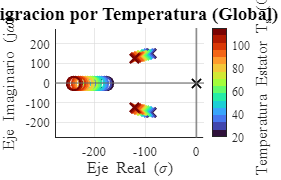


% =========================================================================
% --- DIAGRAMA 1: ESCALA GLOBAL (Visualización de Polos y Ceros) ---
% =========================================================================
plotter_Ts = SignalPlotter("docs/img/");
etiqueta_colorbar_Ts = 'Temperatura Estator T_s (C)'; 

[fig_Ts_global, ax_Ts_global] = plotter_Ts.plotPoleSweep(...
    polesList_Ts, Ts_sweep, etiqueta_colorbar_Ts, ...
    'Title', 'Migracion por Temperatura (Global)');

hold(ax_Ts_global, 'on');

% Agregamos el integrador fijo
scatter(ax_Ts_global, p1_nom, 0, 100, 'x', 'MarkerEdgeColor', 'k', 'LineWidth', 1.5, 'HandleVisibility', 'off');

% Dibujamos la migración del Cero (z_d) manualmente con el mismo colormap
colores_Ts = turbo(num_steps);

% Trayectoria del cero
plot(ax_Ts_global, zd_Ts_array, zeros(num_steps, 1), '--', 'Color', [0.6 0.6 0.6], 'LineWidth', 1, 'HandleVisibility', 'off');

% Puntos del cero variando color
for i = 1:num_steps
    scatter(ax_Ts_global, zd_Ts_array(i), 0, 100, 'o', 'MarkerEdgeColor', colores_Ts(i, :), 'LineWidth', 1.5, 'HandleVisibility', 'off');
end

% Ajuste de límites dinámico (El cero se mueve mucho hacia la izquierda)
xlim_min_sweep_Ts = min(zd_Ts_array) * 1.15;
xlim(ax_Ts_global, [xlim_min_sweep_Ts, 15]);
ylim(ax_Ts_global, [-(wn_nom * 1.6), (wn_nom * 1.6)]);   
hold(ax_Ts_global, 'off');

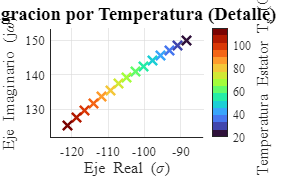


% =========================================================================
% --- DIAGRAMA 2: ZOOM EN EL POLO SUPERIOR ---
% =========================================================================
partes_reales_Ts = cellfun(@(p) real(p(1)), polesList_Ts);
partes_imags_Ts  = cellfun(@(p) imag(p(1)), polesList_Ts);

margen_real_Ts = abs(max(partes_reales_Ts) - min(partes_reales_Ts)) * 0.15;
margen_imag_Ts = abs(max(partes_imags_Ts) - min(partes_imags_Ts)) * 0.15;
if margen_real_Ts == 0, margen_real_Ts = 0.01; end 
if margen_imag_Ts == 0, margen_imag_Ts = 0.01; end

[fig_Ts_zoom, ax_Ts_zoom] = plotter_Ts.plotPoleSweep(...
    polesList_Ts, Ts_sweep, etiqueta_colorbar_Ts, ...
    'Title', 'Migracion por Temperatura (Detalle)');

xlim(ax_Ts_zoom, [min(partes_reales_Ts) - margen_real_Ts, max(partes_reales_Ts) + margen_real_Ts]);
ylim(ax_Ts_zoom, [min(partes_imags_Ts) - margen_imag_Ts, max(partes_imags_Ts) + margen_imag_Ts]);




%plotter_Ts.export(fig_Ts_global, 'mapa_pz_migracion_Ts_global.pdf');
%plotter_Ts.export(fig_Ts_zoom, 'mapa_pz_migracion_Ts_zoom.pdf');

## 4. ANÁLISIS DE OBSERVABILIDAD COMPLETA DE ESTADO

syms beta_m gamma_m nu_e alpha_q alpha_d alpha_T real positive

% Matriz de Estado (A_LTI)
A_sym = [ 0,         1,        0,         0,         0;
          0,   -beta_m,  gamma_m,         0,         0;
          0,     -nu_e, -alpha_q,         0,         0;
          0,         0,        0,  -alpha_d,         0;
          0,         0,        0,         0,  -alpha_T ];

disp('Matriz de Estado A_LTI (Simbólica):')

Matriz de Estado A_LTI (Simbólica):


A_sym

$$A\_sym = \left(\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0\\ 0 & -\beta_{m} & \gamma_{m} & 0 & 0\\ 0 & -\nu_{e} & -\alpha_{q} & 0 & 0\\ 0 & 0 & 0 & -\alpha_{d} & 0\\ 0 & 0 & 0 & 0 & -\alpha_{T} \end{array}\right)$$

### 4.a) Observabilidad utilizando Encoder (Posición theta_m)

% Matriz de salida extrayendo el primer estado
C_theta = [1, 0, 0, 0, 0];

% Construcción de la Matriz de Observabilidad
% O = [C; CA; CA^2; CA^3; CA^4]
O_theta_sym = [ C_theta;
                C_theta * A_sym;
                C_theta * A_sym^2;
                C_theta * A_sym^3;
                C_theta * A_sym^4 ];


disp('Matriz de Observabilidad O_theta (Simbólica):')

Matriz de Observabilidad O_theta (Simbólica):


O_theta_sym_simplificada = simplify(O_theta_sym)

$$O\_theta\_sym\_simplificada = \left(\begin{array}{ccccc} 1 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0\\ 0 & -\beta_{m} & \gamma_{m} & 0 & 0\\ 0 & {\beta_{m}}^{2}-\gamma_{m}\,\nu_{e} & -\gamma_{m}\,\left(\alpha_{q}+\beta_{m}\right) & 0 & 0\\ 0 & -{\beta_{m}}^{3}+2\,\gamma_{m}\,\nu_{e}\,\beta_{m}+\alpha_{q}\,\gamma_{m}\,\nu_{e} & \beta_{m}\,\left(\alpha_{q}\,\gamma_{m}+\beta_{m}\,\gamma_{m}\right)-\gamma_{m}\,\left(\gamma_{m}\,\nu_{e}-{\alpha_{q}}^{2}\right) & 0 & 0 \end{array}\right)$$


% Cálculo del Rango y Espacio Nulo (Estados ocultos)
rango_theta = rank(O_theta_sym_simplificada);
nulo_theta  = null(O_theta_sym_simplificada);

disp('======================================================');

fprintf('RESULTADOS CASO A (Encoder - Posición):\n');

RESULTADOS CASO A (Encoder - Posición):


fprintf('-> Rango de O_theta: %d (Faltan %d dimensiones)\n', double(rango_theta), 5 - double(rango_theta));

-> Rango de O_theta: 3 (Faltan 2 dimensiones)


disp('-> Base del Espacio Nulo (Vectores inobservables):');

-> Base del Espacio Nulo (Vectores inobservables):


disp(nulo_theta)

$$\left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ 1 & 0\\ 0 & 1 \end{array}\right)$$

disp('Interpretación: Los estados x4 (i_ds) y x5 (T_s) son inobservables.');

Interpretación: Los estados x4 (i_ds) y x5 (T_s) son inobservables.


disp('======================================================');

### 4.b) Observabilidad utilizando Tacogenerador (Velocidad omega_m)

% Matriz de salida extrayendo el segundo estado
C_omega = [0, 1, 0, 0, 0];

% Construcción MANUAL de la Matriz de Observabilidad Simbólica
O_omega_sym = [ C_omega;
                C_omega * A_sym;
                C_omega * A_sym^2;
                C_omega * A_sym^3;
                C_omega * A_sym^4 ];

disp('Matriz de Observabilidad O_omega (Simbólica):')

Matriz de Observabilidad O_omega (Simbólica):


O_omega_sym_simplificada = simplify(O_omega_sym)

$$O\_omega\_sym\_simplificada = \begin{array}{l} \left(\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0\\ 0 & -\beta_{m} & \gamma_{m} & 0 & 0\\ 0 & {\beta_{m}}^{2}-\gamma_{m}\,\nu_{e} & -\gamma_{m}\,\left(\alpha_{q}+\beta_{m}\right) & 0 & 0\\ 0 & -{\beta_{m}}^{3}+2\,\gamma_{m}\,\nu_{e}\,\beta_{m}+\alpha_{q}\,\gamma_{m}\,\nu_{e} & \beta_{m}\,\sigma_{1}-\gamma_{m}\,\left(\gamma_{m}\,\nu_{e}-{\alpha_{q}}^{2}\right) & 0 & 0\\ 0 & {\left(\gamma_{m}\,\nu_{e}-{\beta_{m}}^{2}\right)}^{2}-\sigma_{1}\,\left(\alpha_{q}\,\nu_{e}+\beta_{m}\,\nu_{e}\right) & -\gamma_{m}\,\left(\alpha_{q}+\beta_{m}\right)\,\left({\alpha_{q}}^{2}+{\beta_{m}}^{2}-2\,\gamma_{m}\,\nu_{e}\right) & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\alpha_{q}\,\gamma_{m}+\beta_{m}\,\gamma_{m} \end{array}$$


% Cálculo del Rango y Espacio Nulo (Estados ocultos)
rango_omega = rank(O_omega_sym_simplificada);
nulo_omega  = null(O_omega_sym_simplificada);

disp('======================================================');

fprintf('RESULTADOS CASO B (Tacogenerador - Velocidad):\n');

RESULTADOS CASO B (Tacogenerador - Velocidad):


fprintf('-> Rango de O_omega: %d (Faltan %d dimensiones)\n', double(rango_omega), 5 - double(rango_omega));

-> Rango de O_omega: 2 (Faltan 3 dimensiones)


disp('-> Base del Espacio Nulo (Vectores inobservables):');

-> Base del Espacio Nulo (Vectores inobservables):


disp(nulo_omega)

$$\left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

disp('Interpretación: Los estados x1 (theta_m), x4 (i_ds) y x5 (T_s) son inobservables.');

Interpretación: Los estados x1 (theta_m), x4 (i_ds) y x5 (T_s) son inobservables.


disp('======================================================');


%% Validación Numerica
A_num = [ 0, 1, 0, 0, 0;
          0, -beq_nom/Jeq_nom, K_t/Jeq_nom, 0, 0;
          0, -K_v/L_q, -Rs_REF/L_q, 0, 0;
          0, 0, 0, -Rs_REF/L_d, 0;
          0, 0, 0, 0, -1/(Rts_amb*Cts) ];

O_theta_num = obsv(A_num, C_theta);
O_omega_num = obsv(A_num, C_omega);

% Calculamos la inobservabilidad numérica
estados_ocultos_pos = length(A_num) - rank(O_theta_num);
estados_ocultos_vel = length(A_num) - rank(O_omega_num);

fprintf('\n=== VALIDACIÓN NUMÉRICA NOMINAL ===\n');


=== VALIDACIÓN NUMÉRICA NOMINAL ===


fprintf('Midiendo Posición : Estados inobservables = %d\n', estados_ocultos_pos);

Midiendo Posición : Estados inobservables = 2


fprintf('Midiendo Velocidad: Estados inobservables = %d\n', estados_ocultos_vel);

Midiendo Velocidad: Estados inobservables = 3


## 5. COMPENSACIÓN ELECTROMAGNÉTICA Y CONTROL PROPORCIONAL (Lazo Interno)

disp('--- 5.3 Evaluación Numérica y Respuesta Temporal ---')

--- 5.3 Evaluación Numérica y Respuesta Temporal ---


R_q_num = -p_c * L_q;
R_d_num = -p_c * L_d;
R_0_num = -p_c * L_l;
s_tf = tf('s');

G_cl_q = (R_q_num / L_q) / (s_tf + (R_q_num / L_q));
G_ol_q = 1 / (L_q * s_tf + Rs_REF);

% --- Calculo de polos naturales ---
K_grav = (g * kl_nom) / r^2;
coef_nat_estricto = [L_q*Jeq_nom, (Rs_REF*Jeq_nom + L_q*beq_nom), (Rs_REF*beq_nom + K_t*K_v + L_q*K_grav), Rs_REF*K_grav];
polos_nat_estrictos = roots(coef_nat_estricto);
polos_mech_pendulo = roots([Jeq_nom, beq_nom, K_grav]); % Péndulo aislado (sin eléctrica)

% IMPRESIÓN ANALÍTICA EN CONSOLA
disp('>>> UBICACIÓN ANALÍTICA DE POLOS (Sistema Estricto):');

>>> UBICACIÓN ANALÍTICA DE POLOS (Sistema Estricto):


fprintf('  * Polos Naturales Acoplados (Electromecánica + Gravedad):\n'); disp(polos_nat_estrictos);

  * Polos Naturales Acoplados (Electromecánica + Gravedad):
   1.0e+02 *

  -0.8846 + 1.4996i
  -0.8846 - 1.4996i
  -0.0005 + 0.0000i



fprintf('  * Polo Eje d (Natural) : %.2f rad/s\n', pd_nom);

  * Polo Eje d (Natural) : -154.55 rad/s


fprintf('  * Cero Perturbación    : %.2f rad/s\n', zd_nom);

  * Cero Perturbación    : -175.86 rad/s


fprintf('  * Polo Térmico         : %.4f rad/s\n', pT_nom);

  * Polo Térmico         : -0.0083 rad/s


fprintf('  * Nuevos Polos Corriente Lazo Cerrado (p_c): %.0f rad/s\n', p_c);

  * Nuevos Polos Corriente Lazo Cerrado (p_c): -5000 rad/s


disp('------------------------------------------------------------');

------------------------------------------------------------


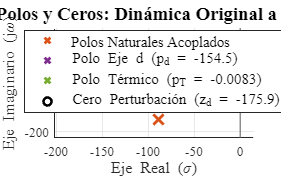


plotter_pz2 = SignalPlotter("docs/img/");

% -------------------------------------------------------------------------
% GRÁFICO 1: EL ANTES (Sistema Natural Acoplado Estricto)
% -------------------------------------------------------------------------
[fig_pz_antes, ax_pz_antes] = plotter_pz2.plotPoleSweep({polos_nat_estrictos}, 1, '', ...
    'Title', 'Mapa de Polos y Ceros: Dinámica Original a Lazo Abierto');
hold(ax_pz_antes, 'on');

% Forzamos el color de los Polos Naturales a Naranja (Palette{2})
h_scatter_antes = findobj(ax_pz_antes, 'Type', 'scatter');
set(h_scatter_antes, 'DisplayName', 'Polos Naturales Acoplados', 'MarkerEdgeColor', plotter_pz2.ColorPalette{2});

% Polo Eje d (Violeta - Palette{4})
scatter(ax_pz_antes, pd_nom, 0, 120, 'x', 'MarkerEdgeColor', plotter_pz2.ColorPalette{4}, 'LineWidth', 2, ...
    'DisplayName', sprintf('Polo Eje d (p_d = %.1f)', pd_nom));

% Polo Térmico (Verde - Palette{5})
scatter(ax_pz_antes, pT_nom, 0, 120, 'x', 'MarkerEdgeColor', plotter_pz2.ColorPalette{5}, 'LineWidth', 2, ...
    'DisplayName', sprintf('Polo Térmico (p_T = %.4f)', pT_nom));

% Cero Perturbación (Negro)
scatter(ax_pz_antes, real(zd_nom), imag(zd_nom), 120, 'o', 'MarkerEdgeColor', 'k', 'LineWidth', 2, ...
    'DisplayName', sprintf('Cero Perturbación (z_d = %.1f)', zd_nom));

% Ajuste de límites
xlim(ax_pz_antes, [min([real(polos_nat_estrictos(1)), zd_nom, pd_nom]) * 1.15, 15]); 
ylim(ax_pz_antes, [-(wd_nom*1.5), (wd_nom*1.5)]); 
legend(ax_pz_antes, 'Location', 'best', 'FontName', plotter_pz2.FontFamily, 'FontSize', plotter_pz2.FontSizeLegend);
hold(ax_pz_antes, 'off');

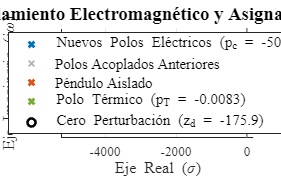


% -------------------------------------------------------------------------
% GRÁFICO 2: EL DESPUÉS (Corrientes Desacopladas y Controladas)
% -------------------------------------------------------------------------
[fig_pz_despues, ax_pz_despues] = plotter_pz2.plotPoleSweep({p_c}, 1, '', ...
    'Title', 'Desacoplamiento Electromagnético y Asignación de Polos');
hold(ax_pz_despues, 'on');

% Nuevos Polos Eléctricos (Azul - Palette{1})
h_scatter_despues = findobj(ax_pz_despues, 'Type', 'scatter');
set(h_scatter_despues, 'DisplayName', sprintf('Nuevos Polos Eléctricos (p_c = %.0f)', p_c), 'MarkerEdgeColor', plotter_pz2.ColorPalette{1});

% Fantasmas y Trayectorias (Gris)
scatter(ax_pz_despues, real(polos_nat_estrictos), imag(polos_nat_estrictos), 120, 'x', 'MarkerEdgeColor', [0.7 0.7 0.7], 'LineWidth', 1.5, ...
    'DisplayName', 'Polos Acoplados Anteriores');
plot(ax_pz_despues, [real(polos_nat_estrictos(1)), p_c], [imag(polos_nat_estrictos(1)), 0], ':', 'Color', [0.6 0.6 0.6], 'LineWidth', 1.2, 'HandleVisibility', 'off');
plot(ax_pz_despues, [real(polos_nat_estrictos(2)), p_c], [imag(polos_nat_estrictos(2)), 0], ':', 'Color', [0.6 0.6 0.6], 'LineWidth', 1.2, 'HandleVisibility', 'off');
plot(ax_pz_despues, [real(polos_nat_estrictos(3)), p_c], [imag(polos_nat_estrictos(3)), 0], ':', 'Color', [0.6 0.6 0.6], 'LineWidth', 1.2, 'HandleVisibility', 'off');

% Péndulo Aislado: Tras controlar corriente, la mecánica que queda NO es solo fricción, es fricción+gravedad
scatter(ax_pz_despues, real(polos_mech_pendulo), imag(polos_mech_pendulo), 120, 'x', 'MarkerEdgeColor', plotter_pz2.ColorPalette{2}, 'LineWidth', 2, ...
    'DisplayName', 'Péndulo Aislado');

% Polos que no se inmutan
scatter(ax_pz_despues, pT_nom, 0, 120, 'x', 'MarkerEdgeColor', plotter_pz2.ColorPalette{5}, 'LineWidth', 2, ...
    'DisplayName', sprintf('Polo Térmico (p_T = %.4f)', pT_nom));
scatter(ax_pz_despues, real(zd_nom), imag(zd_nom), 120, 'o', 'MarkerEdgeColor', 'k', 'LineWidth', 2, ...
    'DisplayName', sprintf('Cero Perturbación (z_d = %.1f)', zd_nom));

xlim(ax_pz_despues, [p_c * 1.05, 200]); 
ylim(ax_pz_despues, [-1500, 1500]); 
legend(ax_pz_despues, 'Location', 'best', 'FontName', plotter_pz2.FontFamily, 'FontSize', plotter_pz2.FontSizeLegend);
hold(ax_pz_despues, 'off');

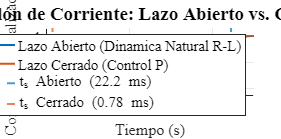


% =========================================================================
% --- RESPUESTA TEMPORAL COMPARATIVA ---
% =========================================================================
G_ol_q_norm = G_ol_q * Rs_REF;
t_sim = (0:1e-5:0.025)'; 
y_ol = step(G_ol_q_norm, t_sim);
y_cl = step(G_cl_q, t_sim);
Y_comp = [y_ol, y_cl];

[fig_step2, ax_step2] = plotter_pz2.plotTime(t_sim, Y_comp, ...
    'Title', 'Respuesta al Escalón de Corriente: Lazo Abierto vs. Control Proporcional', ...
    'XLabel', 'Tiempo (s)', 'YLabel', 'Corriente Normalizada', ...
    'Legends', {'Lazo Abierto (Dinamica Natural R-L)', 'Lazo Cerrado (Control P)'});

info_ol = stepinfo(G_ol_q_norm); 
info_cl = stepinfo(G_cl_q);

hold(ax_step2, 'on');
xline(ax_step2, info_ol.SettlingTime, '--', 'Color', plotter_pz2.ColorPalette{1}, 'LineWidth', 1.5, ...
    'DisplayName', sprintf('t_s Abierto (%.1f ms)', info_ol.SettlingTime * 1000));
xline(ax_step2, info_cl.SettlingTime, '--', 'Color', plotter_pz2.ColorPalette{2}, 'LineWidth', 1.5, ...
    'DisplayName', sprintf('t_s Cerrado (%.2f ms)', info_cl.SettlingTime * 1000));

legend(ax_step2, 'Location', 'southeast', 'FontName', plotter_pz2.FontFamily, 'FontSize', plotter_pz2.FontSizeLegend);
hold(ax_step2, 'off');



% EXPORTAR FIGURAS
%plotter_Ts.export(fig_pz_antes, 'mapa_pz_sistema_no_lineal_completo.pdf');
%plotter_Ts.export(fig_pz_despues, 'mapa_pz_sistema_corriente_controlada.pdf');
%plotter_Ts.export(fig_step2, 'fig_rta_step_original_vs_control_p_corriente.pdf');

## 6. COMPENSACIÓN MECÁNICA Y MODULADOR DE TORQUE (Lazo Externo)

disp('--- 6.3 Evaluación Numérica del Desacoplamiento Mecánico ---')

--- 6.3 Evaluación Numérica del Desacoplamiento Mecánico ---



% 1. Cálculo del modelo estricto (Péndulo acoplado por gravedad)
K_grav = (g * kl_nom) / r^2;
polos_mech_pendulo = roots([Jeq_nom, beq_nom, K_grav]); % Péndulo antes de compensar
polos_mech_comp = [0; 0]; % Doble integrador en el origen tras compensar

% Funciones de transferencia para la respuesta temporal
G_mech_w_ol = tf([1 0], [Jeq_nom, beq_nom, K_grav]);  % Péndulo Natural
G_mech_w_comp = tf(1, [Jeq_nom, 0]);                  % Inercia Compensada

% IMPRESIÓN ANALÍTICA EN CONSOLA
disp('>>> UBICACIÓN ANALÍTICA DE POLOS (Lazo Mecánico):');

>>> UBICACIÓN ANALÍTICA DE POLOS (Lazo Mecánico):


fprintf('  * Péndulo Aislado (Fricción + Gravedad):\n'); disp(polos_mech_pendulo);

  * Péndulo Aislado (Fricción + Gravedad):
  -0.5546 + 2.8806i
  -0.5546 - 2.8806i



fprintf('  * Mecánica Compensada (Doble Integrador):\n'); disp(polos_mech_comp);

  * Mecánica Compensada (Doble Integrador):
     0
     0



disp('------------------------------------------------------------');

------------------------------------------------------------


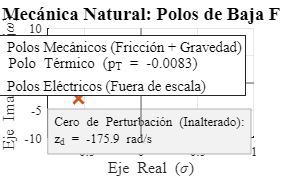


% =========================================================================
% --- DIAGRAMAS DE POLOS: EL ANTES Y EL DESPUÉS (Lazo Mecánico) ---
% =========================================================================
plotter_mech_pz = SignalPlotter("docs/img/");

% Límite izquierdo dinámico basado en los polos lentos
limite_izq_mech = min([real(polos_mech_pendulo(1)), pT_nom]) * 1.5; 

% Texto descriptivo para el Cero de Perturbación
txt_zd = sprintf('Cero de Perturbación (Inalterado):\nz_d = %.1f rad/s', zd_nom);

% -------------------------------------------------------------------------
% GRÁFICO 1: EL ANTES (Mecánica Estricta - Péndulo Amortiguado)
% -------------------------------------------------------------------------
[fig_mech_antes, ax_mech_antes] = plotter_mech_pz.plotPoleSweep({polos_mech_pendulo}, 1, '', ...
    'Title', 'Planta Mecánica Natural: Polos de Baja Frecuencia');
hold(ax_mech_antes, 'on');

% Forzamos color del Péndulo (Naranja - Palette{2})
h_scatter_mech_antes = findobj(ax_mech_antes, 'Type', 'scatter');
set(h_scatter_mech_antes, 'DisplayName', 'Polos Mecánicos (Fricción + Gravedad)', 'MarkerEdgeColor', plotter_mech_pz.ColorPalette{2});

% Polos contextuales
scatter(ax_mech_antes, pT_nom, 0, 120, 'x', 'MarkerEdgeColor', plotter_mech_pz.ColorPalette{5}, 'LineWidth', 2, ...
    'DisplayName', sprintf('Polo Térmico (p_T = %.4f)', pT_nom));
scatter(ax_mech_antes, p_c, 0, 120, 'x', 'MarkerEdgeColor', plotter_mech_pz.ColorPalette{1}, 'LineWidth', 2, ...
    'DisplayName', 'Polos Eléctricos (Fuera de escala)');

% OJO: El polo integrador original p1=0 desapareció porque la gravedad lo absorbió
text(ax_mech_antes, 0.03, 0.05, txt_zd, 'Units', 'normalized', 'FontName', plotter_mech_pz.FontFamily, ...
    'FontSize', plotter_mech_pz.FontSizeTicks, 'BackgroundColor', [0.95 0.95 0.95 0.8], 'EdgeColor', [0.7 0.7 0.7], 'Margin', 4);

xlim(ax_mech_antes, [limite_izq_mech, 1]); 
ylim(ax_mech_antes, [-10, 10]); 
legend(ax_mech_antes, 'Location', 'northeast', 'FontName', plotter_mech_pz.FontFamily, 'FontSize', plotter_mech_pz.FontSizeLegend);
hold(ax_mech_antes, 'off');

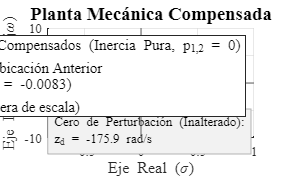


% -------------------------------------------------------------------------
% GRÁFICO 2: EL DESPUÉS (Mecánica Compensada - Doble Integrador)
% -------------------------------------------------------------------------
[fig_mech_despues, ax_mech_despues] = plotter_mech_pz.plotPoleSweep({polos_mech_comp}, 1, '', ...
    'Title', 'Planta Mecánica Compensada');
hold(ax_mech_despues, 'on');

% Forzamos color del Doble Integrador (Negro para destacar el Origen absoluto)
h_scatter_mech_despues = findobj(ax_mech_despues, 'Type', 'scatter');
set(h_scatter_mech_despues, 'DisplayName', 'Polos Mecánicos Compensados (Inercia Pura, p_{1,2} = 0)', 'MarkerEdgeColor', 'k');

% Fantasmas y trayectorias del colapso pendular hacia el origen (Gris)
scatter(ax_mech_despues, real(polos_mech_pendulo), imag(polos_mech_pendulo), 120, 'x', 'MarkerEdgeColor', [0.7 0.7 0.7], 'LineWidth', 1.5, ...
    'DisplayName', 'Polos Mecánicos: Ubicación Anterior');
plot(ax_mech_despues, [real(polos_mech_pendulo(1)), 0], [imag(polos_mech_pendulo(1)), 0], ':', 'Color', [0.6 0.6 0.6], 'LineWidth', 1.2, 'HandleVisibility', 'off');
plot(ax_mech_despues, [real(polos_mech_pendulo(2)), 0], [imag(polos_mech_pendulo(2)), 0], ':', 'Color', [0.6 0.6 0.6], 'LineWidth', 1.2, 'HandleVisibility', 'off');

% Polos contextuales
scatter(ax_mech_despues, pT_nom, 0, 120, 'x', 'MarkerEdgeColor', plotter_mech_pz.ColorPalette{5}, 'LineWidth', 2, ...
    'DisplayName', sprintf('Polo Térmico (p_T = %.4f)', pT_nom));
scatter(ax_mech_despues, p_c, 0, 120, 'x', 'MarkerEdgeColor', plotter_mech_pz.ColorPalette{1}, 'LineWidth', 2, ...
    'DisplayName', 'Polos Eléctricos (Fuera de escala)');

text(ax_mech_despues, 0.03, 0.05, txt_zd, 'Units', 'normalized', 'FontName', plotter_mech_pz.FontFamily, ...
    'FontSize', plotter_mech_pz.FontSizeTicks, 'BackgroundColor', [0.95 0.95 0.95 0.8], 'EdgeColor', [0.7 0.7 0.7], 'Margin', 4);

xlim(ax_mech_despues, [limite_izq_mech, 1]); 
ylim(ax_mech_despues, [-10, 10]); 
legend(ax_mech_despues, 'Location', 'northeast', 'FontName', plotter_mech_pz.FontFamily, 'FontSize', plotter_mech_pz.FontSizeLegend);
hold(ax_mech_despues, 'off');

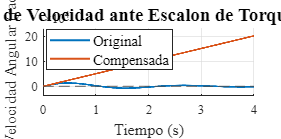


% =========================================================================
% --- RESPUESTA TEMPORAL AL ESCALÓN DE TORQUE ---
% =========================================================================
t_mech = (0:0.001:4)';
y_mech_ol = step(G_mech_w_ol, t_mech);      % Péndulo
y_mech_comp = step(G_mech_w_comp, t_mech);  % Inercia

[fig_mech_step, ax_mech_step] = plotter_mech_pz.plotTime(t_mech, [y_mech_ol, y_mech_comp], ...
    'Title', 'Respuesta de Velocidad ante Escalon de Torque Constante', 'XLabel', 'Tiempo (s)', ...
    'YLabel', 'Velocidad Angular (rad/s)', 'Legends', {'Original', 'Compensada'});
hold(ax_mech_step, 'on');



% EXPORTAR FIGURAS
%plotter_Ts.export(fig_mech_antes, 'mapa_pz_sistema_natural_polos_baja_frec.pdf');
%plotter_Ts.export(fig_mech_despues, 'mapa_pz_sistema_con_torque_compensado.pdf');
%plotter_Ts.export(fig_mech_step, 'fig_rta_step_torque_natural_vs_compensado.pdf');

%% ========================================================================
% 7. LAZO EXTERNO: CONTROLADOR PID DE MOVIMIENTO (POSICIÓN/VELOCIDAD)
% =========================================================================
disp('--- 7.1 Diseño Analítico del Controlador PID ---')

--- 7.1 Diseño Analítico del Controlador PID ---


syms n_sym wn_sym s real positive
syms ba_sym Ksa_sym Ksia_sym real

% Definición del polinomio característico deseado (Filtro Butterworth de 3er orden)
P_deseado = J_eq_sym * (s + wn_sym) * (s^2 + (n_sym - 1)*wn_sym*s + wn_sym^2);
P_deseado_exp = collect(expand(P_deseado), s);

disp('Polinomio Característico Deseado:'); pretty(P_deseado_exp)

Polinomio Característico Deseado:
          3                   2                                 2                  3
J_eq_sym s  + J_eq_sym n_sym s  wn_sym + J_eq_sym n_sym s wn_sym  + J_eq_sym wn_sym




% Ecuaciones de diseño extraídas del polinomio
ba_eq = J_eq_sym * n_sym * wn_sym;
Ksa_eq = J_eq_sym * n_sym * wn_sym^2;
Ksia_eq = J_eq_sym * wn_sym^3;

disp('--- 7.2 Cálculo de Ganancias Numéricas ---')

--- 7.2 Cálculo de Ganancias Numéricas ---


% Requerimientos de la consigna
wn_pid = 800;   % [rad/s]
zeta_pid = 0.75;
n_pid = 2 * zeta_pid + 1; % Dado que zeta = (n-1)/2 => n = 2.5

% Cálculo de ganancias asumiendo inercia nominal a temperatura ambiente
ba_num = Jeq_nom * n_pid * wn_pid;
Ksa_num = Jeq_nom * n_pid * wn_pid^2;
Ksia_num = Jeq_nom * wn_pid^3;

fprintf('Ganancia de Velocidad (b_a)   = %.4f N.m/(rad/s)\n', ba_num);

Ganancia de Velocidad (b_a)   = 0.0396 N.m/(rad/s)


fprintf('Ganancia Proporcional (K_sa)  = %.4f N.m/rad\n', Ksa_num);

Ganancia Proporcional (K_sa)  = 31.6556 N.m/rad


fprintf('Ganancia Integral (K_sia)     = %.2f N.m/(rad.s)\n\n', Ksia_num);

Ganancia Integral (K_sia)     = 10129.78 N.m/(rad.s)




disp('--- 7.3 Análisis de Migración de Polos (Robustez ante J_eq) ---')

--- 7.3 Análisis de Migración de Polos (Robustez ante J_eq) ---


% Polinomio característico: J_eq*s^3 + ba*s^2 + Ksa*s + Ksia = 0
polos_pid_nom = roots([Jeq_nom, ba_num, Ksa_num, Ksia_num]);
polos_pid_min = roots([Jeq_min, ba_num, Ksa_num, Ksia_num]);
polos_pid_max = roots([Jeq_max, ba_num, Ksa_num, Ksia_num]);

% IMPRESIÓN ANALÍTICA EN CONSOLA
disp('>>> UBICACIÓN ANALÍTICA DE POLOS (Lazo de Movimiento):');

>>> UBICACIÓN ANALÍTICA DE POLOS (Lazo de Movimiento):


fprintf('  * PID con Inercia Nominal:\n'); disp(polos_pid_nom);

  * PID con Inercia Nominal:
   1.0e+02 *

  -8.0000 + 0.0000i
  -6.0000 + 5.2915i
  -6.0000 - 5.2915i



fprintf('  * PID con Inercia Mínima (Carga Vacía):\n'); disp(polos_pid_min);

  * PID con Inercia Mínima (Carga Vacía):
   1.0e+02 *

  -8.0000 + 0.0000i
  -6.0000 + 5.2915i
  -6.0000 - 5.2915i



fprintf('  * PID con Inercia Máxima (Carga Plena):\n'); disp(polos_pid_max);

  * PID con Inercia Máxima (Carga Plena):
   1.0e+02 *

  -2.1262 + 6.7765i
  -2.1262 - 6.7765i
  -4.3822 + 0.0000i



disp('------------------------------------------------------------');

------------------------------------------------------------


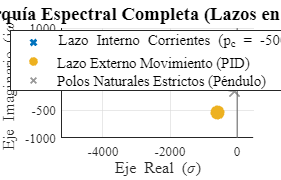


% =========================================================================
% --- DIAGRAMA DE POLOS: COMPARATIVA GLOBAL (JERARQUÍA ESPECTRAL) ---
% =========================================================================
plotter_pid = SignalPlotter("docs/img/");
[fig_pid_global, ax_pid_global] = plotter_pid.plotPoleSweep({p_c}, 1, '', ...
    'Title', 'Jerarquía Espectral Completa (Lazos en Cascada)');
hold(ax_pid_global, 'on');

% 1. Lazo Interno (Ultrarrápido) - Forzado a Azul (Palette{1})
h_scatter_global = findobj(ax_pid_global, 'Type', 'scatter');
set(h_scatter_global, 'DisplayName', sprintf('Lazo Interno Corrientes (p_c = %.0f)', p_c), 'MarkerEdgeColor', plotter_pid.ColorPalette{1});

% 2. Lazo Externo (Dinámica Dominante Controlada) - Amarillo/Dorado (Palette{3})
scatter(ax_pid_global, real(polos_pid_nom), imag(polos_pid_nom), 100, 'o', 'MarkerEdgeColor', plotter_pid.ColorPalette{3}, 'MarkerFaceColor', plotter_pid.ColorPalette{3}, ...
    'DisplayName', 'Lazo Externo Movimiento (PID)');

% 3. Ecosistema Natural Original (Para referencia del "Antes")
scatter(ax_pid_global, real(polos_nat_estrictos), imag(polos_nat_estrictos), 120, 'x', 'MarkerEdgeColor', [0.6 0.6 0.6], 'LineWidth', 1.5, ...
    'DisplayName', 'Polos Naturales Estrictos (Péndulo)');
scatter(ax_pid_global, pd_nom, 0, 120, 'x', 'MarkerEdgeColor', [0.6 0.6 0.6], 'LineWidth', 1.5, ...
    'HandleVisibility', 'off'); % Oculto en leyenda para no saturar
scatter(ax_pid_global, pT_nom, 0, 120, 'x', 'MarkerEdgeColor', [0.6 0.6 0.6], 'LineWidth', 1.5, ...
    'HandleVisibility', 'off');
scatter(ax_pid_global, real(zd_nom), imag(zd_nom), 120, 'o', 'MarkerEdgeColor', [0.6 0.6 0.6], 'LineWidth', 1.5, ...
    'HandleVisibility', 'off');

% Ajuste de límites (Vista Global Macro)
xlim(ax_pid_global, [p_c * 1.05, 500]);
ylim(ax_pid_global, [-1000, 1000]); 
legend(ax_pid_global, 'Location', 'best', 'FontName', plotter_pid.FontFamily, 'FontSize', plotter_pid.FontSizeLegend);
hold(ax_pid_global, 'off');

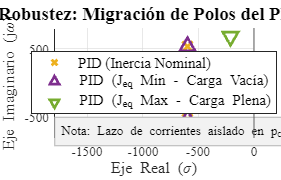


% =========================================================================
% --- DIAGRAMA DE POLOS: ZOOM ZONA PID (INCERTIDUMBRE MECÁNICA) ---
% =========================================================================
[fig_pid_zoom, ax_pid_zoom] = plotter_pid.plotPoleSweep({polos_pid_nom}, 1, '', ...
    'Title', 'Análisis de Robustez: Migración de Polos del PID ante Inercia');
hold(ax_pid_zoom, 'on');

% Nominal - Forzado a Palette{3} para mantener coherencia con el global
h_scatter_zoom = findobj(ax_pid_zoom, 'Type', 'scatter');
set(h_scatter_zoom, 'DisplayName', 'PID (Inercia Nominal)', 'MarkerEdgeColor', plotter_pid.ColorPalette{3}, 'MarkerFaceColor', plotter_pid.ColorPalette{3});

% Variaciones paramétricas
scatter(ax_pid_zoom, real(polos_pid_min), imag(polos_pid_min), 100, '^', 'MarkerEdgeColor', plotter_pid.ColorPalette{4}, 'LineWidth', 2, ...
    'DisplayName', 'PID (J_{eq} Min - Carga Vacía)');
scatter(ax_pid_zoom, real(polos_pid_max), imag(polos_pid_max), 100, 'v', 'MarkerEdgeColor', plotter_pid.ColorPalette{5}, 'LineWidth', 2, ...
    'DisplayName', 'PID (J_{eq} Max - Carga Plena)');

% Nota sobre la separación espectral
txt_sep = sprintf('Nota: Lazo de corrientes aislado en p_c = %.0f rad/s', p_c);
text(ax_pid_zoom, 0.03, 0.05, txt_sep, 'Units', 'normalized', 'FontName', plotter_pid.FontFamily, ...
    'FontSize', plotter_pid.FontSizeTicks, 'BackgroundColor', [0.95 0.95 0.95 0.8], 'EdgeColor', [0.7 0.7 0.7], 'Margin', 4);

% Ajuste sobre la zona de interés
xlim(ax_pid_zoom, [-1800, 0]);
ylim(ax_pid_zoom, [-800, 800]); 
legend(ax_pid_zoom, 'Location', 'best', 'FontName', plotter_pid.FontFamily, 'FontSize', plotter_pid.FontSizeLegend);
hold(ax_pid_zoom, 'off');


% =========================================================================
% --- 7.4 RESPUESTA TEMPORAL: LAZO INTERNO DE VELOCIDAD ---
% =========================================================================
disp('--- 7.4 Validación del Lazo Secundario (Control de Velocidad) ---')

--- 7.4 Validación del Lazo Secundario (Control de Velocidad) ---


s_tf = tf('s');

% El lazo interno de velocidad opera como un controlador PI.
% C_v(s) = b_a + K_sa / s.  (Ignoramos temporalmente el integrador de posición K_sia)
G_w_cl_nom = (ba_num*s_tf + Ksa_num) / (Jeq_nom*s_tf^2 + ba_num*s_tf + Ksa_num);
G_w_cl_min = (ba_num*s_tf + Ksa_num) / (Jeq_min*s_tf^2 + ba_num*s_tf + Ksa_num);
G_w_cl_max = (ba_num*s_tf + Ksa_num) / (Jeq_max*s_tf^2 + ba_num*s_tf + Ksa_num);

% Simulamos un escalón unitario de velocidad (w_m^* = 1 rad/s)
t_vel = (0:1e-5:0.015)';
y_w_nom = step(G_w_cl_nom, t_vel);
y_w_min = step(G_w_cl_min, t_vel);
y_w_max = step(G_w_cl_max, t_vel);

Y_w_comp = [y_w_min, y_w_nom, y_w_max];

[fig_step_vel, ax_step_vel] = plotter_pid.plotTime(t_vel, Y_w_comp, ...
    'Title', 'Respuesta a Escalón de Velocidad (\omega_m^* = 1 rad/s)', ...
    'XLabel', 'Tiempo (s)', ...
    'YLabel', 'Velocidad Angular \omega_m (rad/s)', ...
    'Legends', {'Inercia Mínima', 'Inercia Nominal', 'Inercia Máxima'});

% Forzamos la leyenda a la esquina inferior derecha
legend(ax_step_vel, 'Location', 'southeast', 'FontName', plotter_pid.FontFamily, 'FontSize', plotter_pid.FontSizeLegend);

% Extraer métricas nominales del lazo de velocidad
info_w_nom = stepinfo(G_w_cl_nom);
fprintf('--- Lazo de Velocidad (Nominal) ---\n');

--- Lazo de Velocidad (Nominal) ---


fprintf('Tiempo de Asentamiento : %.2f ms\n', info_w_nom.SettlingTime * 1000);

Tiempo de Asentamiento : 3.98 ms


fprintf('Sobreimpulso Máximo    : %.2f %%\n\n', info_w_nom.Overshoot);

Sobreimpulso Máximo    : 18.24 %



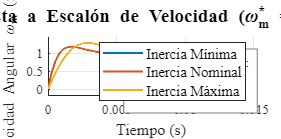


txt_perf_w = {sprintf('Desempeño Nominal:'), ...
              sprintf('t_s = %.2f ms', info_w_nom.SettlingTime * 1000), ...
              sprintf('OS  = %.1f %%', info_w_nom.Overshoot)};
              
% Reubicamos la caja de texto en el centro-abajo para evitar superposición
text(ax_step_vel, 0.40, 0.25, txt_perf_w, 'Units', 'normalized', 'FontName', plotter_pid.FontFamily, ...
    'FontSize', plotter_pid.FontSizeTicks, 'BackgroundColor', [1 1 1 0.9], 'EdgeColor', [0.5 0.5 0.5], 'Margin', 5);


% =========================================================================
% --- 7.5 RESPUESTA TEMPORAL: LAZO EXTERNO DE POSICIÓN (GLOBAL) ---
% =========================================================================
disp('--- 7.5 Validación del Lazo Principal (Control de Posición) ---')

--- 7.5 Validación del Lazo Principal (Control de Posición) ---



% Funciones de transferencia de Lazo Cerrado Global (Posición Theta)
G_theta_cl_nom = (ba_num*s_tf^2 + Ksa_num*s_tf + Ksia_num) / (Jeq_nom*s_tf^3 + ba_num*s_tf^2 + Ksa_num*s_tf + Ksia_num);
G_theta_cl_min = (ba_num*s_tf^2 + Ksa_num*s_tf + Ksia_num) / (Jeq_min*s_tf^3 + ba_num*s_tf^2 + Ksa_num*s_tf + Ksia_num);
G_theta_cl_max = (ba_num*s_tf^2 + Ksa_num*s_tf + Ksia_num) / (Jeq_max*s_tf^3 + ba_num*s_tf^2 + Ksa_num*s_tf + Ksia_num);

% Simulamos un escalón unitario de referencia interna (\theta_m^* = 1 rad)
t_pos = (0:1e-5:0.025)';
y_pos_nom = step(G_theta_cl_nom, t_pos);
y_pos_min = step(G_theta_cl_min, t_pos);
y_pos_max = step(G_theta_cl_max, t_pos);

Y_pos_comp = [y_pos_min, y_pos_nom, y_pos_max];

[fig_step_pos, ax_step_pos] = plotter_pid.plotTime(t_pos, Y_pos_comp, ...
    'Title', 'Seguimiento de Posición Articular (\theta_m^* = 1 rad)', ...
    'XLabel', 'Tiempo (s)', ...
    'YLabel', 'Posición Angular \theta_m (rad)', ...
    'Legends', {'Inercia Mínima', 'Inercia Nominal', 'Inercia Máxima'});

% Forzamos la leyenda a la esquina inferior derecha
legend(ax_step_pos, 'Location', 'southeast', 'FontName', plotter_pid.FontFamily, 'FontSize', plotter_pid.FontSizeLegend);

% Extraer métricas nominales del lazo de posición
info_pos_nom = stepinfo(G_theta_cl_nom);
fprintf('--- Lazo de Posición (Nominal) ---\n');

--- Lazo de Posición (Nominal) ---


fprintf('Tiempo de Asentamiento : %.2f ms\n', info_pos_nom.SettlingTime * 1000);

Tiempo de Asentamiento : 8.07 ms


fprintf('Sobreimpulso Máximo    : %.2f %%\n\n', info_pos_nom.Overshoot);

Sobreimpulso Máximo    : 24.58 %



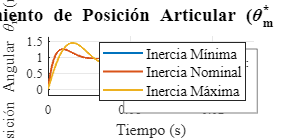


txt_perf_pos = {sprintf('Desempeño Nominal:'), ...
                sprintf('t_s = %.1f ms', info_pos_nom.SettlingTime * 1000), ...
                sprintf('OS  = %.1f %%', info_pos_nom.Overshoot)};

% Reubicamos la caja de texto en el centro-abajo para evitar superposición
text(ax_step_pos, 0.40, 0.25, txt_perf_pos, 'Units', 'normalized', 'FontName', plotter_pid.FontFamily, ...
    'FontSize', plotter_pid.FontSizeTicks, 'BackgroundColor', [1 1 1 0.9], 'EdgeColor', [0.5 0.5 0.5], 'Margin', 5);


% Exportación (Descomentar para generar los PDFs finales)
%plotter_pid.export(fig_pid_global, 'jerarquia_polos_global.pdf');
%plotter_pid.export(fig_pid_zoom, 'migracion_pid_robustez.pdf');
%plotter_pid.export(fig_step_vel, 'respuesta_escalon_velocidad_pid.pdf');
%plotter_pid.export(fig_step_pos, 'respuesta_escalon_posicion_pid.pdf');


## 8. OBSERVADOR DE ESTADO CINEMÁTICO (ESTIMADOR DE VELOCIDAD)

En esta sección se analiza la dinámica de estimación como un subsistema aislado. 

El rendimiento global en lazo cerrado (Planta + PID + Observador) frente a perturbaciones se evaluará posteriormente en el entorno de simulación.

% Parámetros globales de simulación para los tres casos
t_obs = (0:1e-6:0.005)'; 
d_perturbacion = 0.05 * ones(size(t_obs)); % Perturbación física constante d(t) [N.m]
cond_ini_std = [0.1; 50];    % [e_theta; e_omega] inicial
cond_ini_ext = [0.1; 50; 0]; % [e_theta; e_omega; z] inicial

plotter_obs = SignalPlotter("docs/img/");

%% ========================================================================
% --- 8.a CONSTRUCCIÓN DEL OBSERVADOR ESTÁNDAR (ORDEN 2) ---
% =========================================================================
disp('--- 8.a.1 Síntesis Simbólica del Observador Estándar ---')

--- 8.a.1 Síntesis Simbólica del Observador Estándar ---


syms K_eth K_ew s real
syms J_eq_sym real

% Matrices del sistema de la planta compensada (Inercia Pura)
A_obs = [0, 1; 0, 0];
B_obs = [0; 1/J_eq_sym];
C_obs = [1, 0];

% Matriz de innovación y dinámica del error
K_e_sym = [K_eth; K_ew];
A_err_sym = A_obs - K_e_sym * C_obs;

P_obs_sym = collect(det(s*eye(2) - A_err_sym), s);
disp('Polinomio Característico:'); pretty(P_obs_sym)

Polinomio Característico:
 2
s  + K_eth s + K_ew




disp('--- 8.a.2 Cálculo Numérico y Simulación ---')

--- 8.a.2 Cálculo Numérico y Simulación ---


polo_agresivo = -3200;
K_eth_std = 2 * abs(polo_agresivo);
K_ew_std  = abs(polo_agresivo)^2;

fprintf('Ganancias (Polos en %d rad/s):\n', polo_agresivo);

Ganancias (Polos en -3200 rad/s):


fprintf('  K_eth : %d rad/s\n', K_eth_std);

  K_eth : 6400 rad/s


fprintf('  K_ew  : %d rad/s^2\n\n', K_ew_std);

  K_ew  : 10240000 rad/s^2



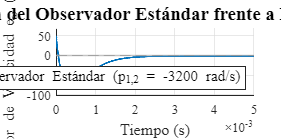


% Simulación
A_std_num = [ -K_eth_std, 1; -K_ew_std, 0 ];
B_d_std_num = [0; 1/Jeq_nom];
sys_error_std = ss(A_std_num, -B_d_std_num, eye(2), [0;0]);

[y_err_std, ~] = lsim(sys_error_std, d_perturbacion, t_obs, cond_ini_std);
e_omega_std = y_err_std(:, 2);

% Gráfica 8.a
[fig_obs_a, ax_obs_a] = plotter_obs.plotTime(t_obs, e_omega_std, ...
    'Title', 'Dinámica del Observador Estándar frente a Perturbación', ...
    'XLabel', 'Tiempo (s)', 'YLabel', 'Error de Velocidad e_\omega (rad/s)', ...
    'Legends', {'Observador Estándar (p_{1,2} = -3200 rad/s)'});

hold(ax_obs_a, 'on');
% Línea visual de referencia en el Cero absoluto
yline(ax_obs_a, 0, '-', 'Color', [0.7 0.7 0.7], 'LineWidth', 1, 'HandleVisibility', 'off');

legend(ax_obs_a, 'Location', 'southeast', 'FontName', plotter_obs.FontFamily, 'FontSize', plotter_obs.FontSizeLegend);
hold(ax_obs_a, 'off');


% Impresión en consola para redactar el informe
e_ss_std = e_omega_std(end);
fprintf('> [Para Informe 8.a] Error residual estándar: %.2f rad/s\n', e_ss_std);

> [Para Informe 8.a] Error residual estándar: -1.58 rad/s





%% ========================================================================
% --- 8.b OBSERVADOR EXTENDIDO: ACCIÓN INTEGRAL (ORDEN 3) ---
% =========================================================================
disp('--- 8.b.1 Síntesis Simbólica del Observador Extendido ---')

--- 8.b.1 Síntesis Simbólica del Observador Extendido ---


syms K_eth_sym K_ew_sym K_ei_sym s real

A_err_ext_sym = [ -K_eth_sym, 1, 0; 
                  -K_ew_sym,  0, 1; 
                  -K_ei_sym,  0, 0 ];

P_obs_ext_sym = collect(det(s*eye(3) - A_err_ext_sym), s);
disp('Polinomio Característico (Extendido):'); pretty(P_obs_ext_sym)

Polinomio Característico (Extendido):
 3              2
s  + K_eth_sym s  + K_ew_sym s + K_ei_sym




disp('--- 8.b.2 Cálculo Numérico y Simulación Comparativa ---')

--- 8.b.2 Cálculo Numérico y Simulación Comparativa ---


% Mantenemos los polos en -3200 rad/s
K_eth_ext_agresivo = 3 * abs(polo_agresivo);
K_ew_ext_agresivo  = 3 * abs(polo_agresivo)^2;
K_ei_ext_agresivo  = abs(polo_agresivo)^3;

fprintf('Ganancias Extendidas (Polos en %d rad/s):\n', polo_agresivo);

Ganancias Extendidas (Polos en -3200 rad/s):


fprintf('  K_eth : %.3e rad/s\n', K_eth_ext_agresivo);

  K_eth : 9.600e+03 rad/s


fprintf('  K_ew  : %.3e rad/s^2\n', K_ew_ext_agresivo);

  K_ew  : 3.072e+07 rad/s^2


fprintf('  K_ei  : %.3e rad/s^3\n\n', K_ei_ext_agresivo);

  K_ei  : 3.277e+10 rad/s^3



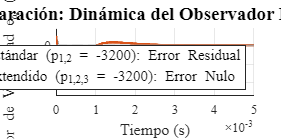


% Simulación
A_ext_agr = [ -K_eth_ext_agresivo, 1, 0; -K_ew_ext_agresivo, 0, -1; K_ei_ext_agresivo, 0, 0 ];
B_d_ext_num = [0; 1/Jeq_nom; 0];
sys_error_ext_agr = ss(A_ext_agr, -B_d_ext_num, eye(3), [0;0;0]);

[y_err_ext_agr, ~] = lsim(sys_error_ext_agr, d_perturbacion, t_obs, cond_ini_ext);
e_omega_ext_agr = y_err_ext_agr(:, 2);

% Gráfica 8.b (Comparativa Estándar vs Extendido)
[fig_obs_b, ax_obs_b] = plotter_obs.plotTime(t_obs, [e_omega_std, e_omega_ext_agr], ...
    'Title', 'Comparación: Dinámica del Observador Extendido', ...
    'XLabel', 'Tiempo (s)', 'YLabel', 'Error de Velocidad e_\omega (rad/s)', ...
    'Legends', {'Estándar (p_{1,2} = -3200): Error Residual', 'Extendido (p_{1,2,3} = -3200): Error Nulo'});

hold(ax_obs_b, 'on');
h_lines_b = findobj(ax_obs_b, 'Type', 'line');
set(h_lines_b(1), 'Color', plotter_obs.ColorPalette{2}, 'LineWidth', 2); % Extendido (Naranja/Rojo)
set(h_lines_b(2), 'Color', [0.5 0.5 0.5], 'LineWidth', 1.5, 'LineStyle', '--'); % Estándar (Gris discontinuo)

yline(ax_obs_b, 0, '-', 'Color', [0.7 0.7 0.7], 'LineWidth', 1, 'HandleVisibility', 'off');

legend(ax_obs_b, 'Location', 'southeast', 'FontName', plotter_obs.FontFamily, 'FontSize', plotter_obs.FontSizeLegend);
hold(ax_obs_b, 'off');


pico_agr = min(e_omega_ext_agr);
fprintf('> [Para Informe 8.b] Pico agresivo (Peaking): %.2f rad/s\n', pico_agr);

> [Para Informe 8.b] Pico agresivo (Peaking): -227.67 rad/s



%% ========================================================================
% --- 8.c AJUSTE FINO: MITIGACIÓN DE PEAKING (POLOS EN -1800) ---
% =========================================================================
disp('--- 8.c.1 Justificación Espectral y Recálculo Numérico ---')

--- 8.c.1 Justificación Espectral y Recálculo Numérico ---


% Justificación: La dinámica dominante del PID está dictada por la parte real
% de sus polos conjugados (-600 rad/s). Aplicando la regla de separación espectral 
% (x3), reubicamos el observador en -1800 rad/s para suavizar el transitorio.

polo_suave = -1800;
K_eth_ext_suave = 3 * abs(polo_suave);
K_ew_ext_suave  = 3 * abs(polo_suave)^2;
K_ei_ext_suave  = abs(polo_suave)^3;

fprintf('Ganancias Extendidas (Polos en %d rad/s):\n', polo_suave);

Ganancias Extendidas (Polos en -1800 rad/s):


fprintf('  K_eth : %.3e rad/s\n', K_eth_ext_suave);

  K_eth : 5.400e+03 rad/s


fprintf('  K_ew  : %.3e rad/s^2\n', K_ew_ext_suave);

  K_ew  : 9.720e+06 rad/s^2


fprintf('  K_ei  : %.3e rad/s^3\n\n', K_ei_ext_suave);

  K_ei  : 5.832e+09 rad/s^3




fprintf('> Regla de Separación Espectral Aplicada:\n');

> Regla de Separación Espectral Aplicada:


fprintf('  Polo Dominante PID   : -600 rad/s\n');

  Polo Dominante PID   : -600 rad/s


fprintf('  Polo Obs. Suavizado  : %d rad/s (Relación: 3x)\n\n', polo_suave);

  Polo Obs. Suavizado  : -1800 rad/s (Relación: 3x)



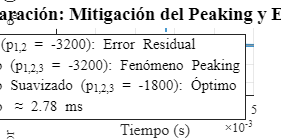


% Simulación
A_ext_sua = [ -K_eth_ext_suave, 1, 0; -K_ew_ext_suave, 0, -1; K_ei_ext_suave, 0, 0 ];
sys_error_ext_sua = ss(A_ext_sua, -B_d_ext_num, eye(3), [0;0;0]);

[y_err_ext_sua, ~] = lsim(sys_error_ext_sua, d_perturbacion, t_obs, cond_ini_ext);
e_omega_ext_sua = y_err_ext_sua(:, 2);

% Gráfica 8.c (Comparativa Global de los 3 casos)
[fig_obs_c, ax_obs_c] = plotter_obs.plotTime(t_obs, [e_omega_std, e_omega_ext_agr, e_omega_ext_sua], ...
    'Title', 'Comparación: Mitigación del Peaking y Error Nulo', ...
    'XLabel', 'Tiempo (s)', 'YLabel', 'Error de Velocidad e_\omega (rad/s)', ...
    'Legends', {'Estándar (p_{1,2} = -3200): Error Residual', ...
                'Extendido (p_{1,2,3} = -3200): Fenómeno Peaking', ...
                'Extendido Suavizado (p_{1,2,3} = -1800): Óptimo'});

hold(ax_obs_c, 'on');

% Configuración cromática y de estilos
h_lines_c = findobj(ax_obs_c, 'Type', 'line');
set(h_lines_c(1), 'Color', plotter_obs.ColorPalette{1}, 'LineWidth', 2.5); % Suavizado: Azul fuerte
set(h_lines_c(2), 'Color', plotter_obs.ColorPalette{2}, 'LineWidth', 1.5, 'LineStyle', '-.'); % Agresivo: Naranja
set(h_lines_c(3), 'Color', [0.5 0.5 0.5], 'LineWidth', 1.5, 'LineStyle', '--'); % Estándar: Gris discontinuo

yline(ax_obs_c, 0, '-', 'Color', [0.7 0.7 0.7], 'LineWidth', 1, 'HandleVisibility', 'off');

t_s_sua = 5 / abs(polo_suave);
xline(ax_obs_c, t_s_sua, '--', 'Color', plotter_obs.ColorPalette{1}, 'LineWidth', 1.5, ...
    'DisplayName', sprintf('t_s Óptimo \\approx %.2f ms', t_s_sua * 1000));

legend(ax_obs_c, 'Location', 'southeast', 'FontName', plotter_obs.FontFamily, 'FontSize', plotter_obs.FontSizeLegend);
hold(ax_obs_c, 'off');


pico_sua = min(e_omega_ext_sua);
fprintf('> [Para Informe 8.c] Pico suavizado: %.2f rad/s\n', pico_sua);

> [Para Informe 8.c] Pico suavizado: -117.45 rad/s


fprintf('> [Para Informe 8.c] Reducción del Peaking: %.1f %%\n', (1 - abs(pico_sua/pico_agr)) * 100);

> [Para Informe 8.c] Reducción del Peaking: 48.4 %



%plotter_obs.export(fig_obs_a, 'fig_observador_estandar_error.pdf');
%plotter_obs.export(fig_obs_b, 'fig_observador_extendido_peaking.pdf');
%plotter_obs.export(fig_obs_c, 'fig_comparativa_global_observadores.pdf');


### 9. MODELADO DE SENSORES NO IDEALES (ESPACIO DE ESTADOS)

En esta sección se degrada el modelo ideal G(s)=1 de los sensores reemplazándolos por filtros pasa-bajos (LP) equivalentes, a fin de evaluar el impacto del ancho de banda limitado en el sistema de control.

disp('--- 9.1 Parámetros y Multiplicadores de Sensibilidad ---')

--- 9.1 Parámetros y Multiplicadores de Sensibilidad ---


% Se incorporan multiplicadores (k_w) para facilitar el análisis de 
% sensibilidad requerido (wn, wn*2, wn*3, etc.)

k_w_i   = 1;   % Multiplicador ancho de banda - Corrientes
k_w_pos = 1;   % Multiplicador ancho de banda - Posición angular

fprintf('Multiplicador de Ancho de Banda (Corrientes) : %dx\n', k_w_i);

Multiplicador de Ancho de Banda (Corrientes) : 1x


fprintf('Multiplicador de Ancho de Banda (Posición)   : %dx\n\n', k_w_pos);

Multiplicador de Ancho de Banda (Posición)   : 1x




%% --- 9.2 Sensor de Corriente (LP 2do Orden) ---
% Requerimientos
wn_i_base = 6000;         % [rad/s]
zeta_i = 1;               % Amortiguamiento crítico
wn_i = wn_i_base * k_w_i; % Frecuencia efectiva

% Matrices Espacio de Estados
A_iabc = [0, -1; 
          wn_i^2, -2*zeta_i*wn_i];
B_iabc = [1; 
          0];
C_iabc = [0, 1];
D_iabc = 0;

disp('--- 9.2 Sensor de Corrientes de Fase (i_as, i_bs, i_cs) ---')

--- 9.2 Sensor de Corrientes de Fase (i_as, i_bs, i_cs) ---


disp('A_iabc ='); disp(A_iabc);

A_iabc =
           0          -1
    36000000      -12000



disp('B_iabc ='); disp(B_iabc);

B_iabc =
     1
     0



disp('C_iabc ='); disp(C_iabc);

C_iabc =
     0     1




%% --- 9.3 Sensor de Posición Angular (LP 2do Orden) ---
% Requerimientos
wn_pos_base = 2000;           % [rad/s]
zeta_pos = 1;                 % Amortiguamiento crítico
wn_pos = wn_pos_base * k_w_pos; % Frecuencia efectiva

% Matrices Espacio de Estados
A_pos = [0, -1; 
         wn_pos^2, -2*zeta_pos*wn_pos];
B_pos = [1; 
         0];
C_pos = [0, 1];
D_pos = 0;

disp('--- 9.3 Sensor de Posición Angular (theta_m) ---')

--- 9.3 Sensor de Posición Angular (theta_m) ---


disp('A_pos ='); disp(A_pos);

A_pos =
           0          -1
     4000000       -4000



disp('B_pos ='); disp(B_pos);

B_pos =
     1
     0



disp('C_pos ='); disp(C_pos);

C_pos =
     0     1




%% --- 9.4 Sensor de Temperatura (LP 1er Orden) ---
% Requerimientos
tau_T = 20; % Constante de tiempo [s]

% Matrices Espacio de Estados
A_T = -1 / tau_T;
B_T = 1;
C_T = 1 / tau_T;
D_T = 0;

disp('--- 9.4 Sensor de Temperatura Térmica (T_s) ---')

--- 9.4 Sensor de Temperatura Térmica (T_s) ---


disp('A_T ='); disp(A_T);

A_T =
   -0.0500



disp('B_T ='); disp(B_T);

B_T =
     1



disp('C_T ='); disp(C_T);

C_T =
    0.0500



disp('D_T ='); disp(D_T);

D_T =
     0



%% ========================================================================
% --- 9.5 CÁLCULO DE CONDICIONES INICIALES PARA SIMULINK ---
% =========================================================================
% Para evitar transitorios iniciales de medición en Simulink, las 
% condiciones iniciales de los integradores (vector X_0) deben 
% calcularse para un estado estacionario (dX/dt = 0).


% Si Y_0 es el valor inicial de la variable física a medir:
% Para el 2do Orden (Posición y Corriente): X_0 = [(2*zeta/wn)*Y_0 ; Y_0]
% Para el 1er Orden (Temperatura): X_0 = [tau * Y_0]

disp('--- 9.5 Condiciones Iniciales en Estado Estacionario (X_0) ---')

--- 9.5 Condiciones Iniciales en Estado Estacionario (X_0) ---


fprintf('Para inyectar en el bloque State-Space de Simulink:\n');

Para inyectar en el bloque State-Space de Simulink:


fprintf('> Sensor Corriente (i_0) : X_0 = [%.2e * i_0 ; i_0]\n', (2*zeta_i)/wn_i);

> Sensor Corriente (i_0) : X_0 = [3.33e-04 * i_0 ; i_0]


fprintf('> Sensor Posición (th_0) : X_0 = [%.2e * th_0 ; th_0]\n', (2*zeta_pos)/wn_pos);

> Sensor Posición (th_0) : X_0 = [1.00e-03 * th_0 ; th_0]


fprintf('> Sensor Temperat. (T_0) : X_0 = [%.2f * T_0]\n\n', tau_T);

> Sensor Temperat. (T_0) : X_0 = [20.00 * T_0]




% Ejemplo numérico asumiendo que el motor arranca en theta = 0 rad y 25°C
theta_0 = 0;
T_0 = 25;
X0_pos_num = [(2*zeta_pos/wn_pos)*theta_0; theta_0];
X0_T_num = tau_T * T_0;

disp('Ejemplo Numérico (Arranque en theta=0, T_0=25°C):');

Ejemplo Numérico (Arranque en theta=0, T_0=25°C):


fprintf('  X0_pos = [%.4f; %.4f]\n', X0_pos_num(1), X0_pos_num(2));

  X0_pos = [0.0000; 0.0000]


fprintf('  X0_T   = [%.1f]\n', X0_T_num);

  X0_T   = [500.0]


%% ========================================================================
% 10. MODELADO DEL INVERSOR NO IDEAL (MODULADOR TRIFÁSICO DE TENSIÓN)
% =========================================================================
% Se degrada el modelo ideal del inversor incorporando la inercia dinámica
% (Ancho de Banda limitado) y las restricciones físicas del Bus DC (Saturación).

disp('--- 10.1 Restricciones Físicas: Saturación de Tensión ---')

--- 10.1 Restricciones Físicas: Saturación de Tensión ---


% Tensión de línea máxima del inversor (según consigna)
V_sl_max = 48; % [Vca rms]

% Límite de tensión pico por fase
% La saturación ocurre en: V_max = sqrt(2) * (V_sl_max / sqrt(3))
V_fase_max = sqrt(2) * (V_sl_max / sqrt(3));

fprintf('Tensión de Línea Máxima Inversor : %d V_rms\n', V_sl_max);

Tensión de Línea Máxima Inversor : 48 V_rms


fprintf('Límite de Saturación por Fase    : +/- %.2f V_pico\n\n', V_fase_max);

Límite de Saturación por Fase    : +/- 39.19 V_pico



disp('NOTA: Este valor de +/- 39.19 V debe ingresarse en los bloques "Saturation" de Simulink.');

NOTA: Este valor de +/- 39.19 V debe ingresarse en los bloques "Saturation" de Simulink.


fprintf('\n');

disp('--- 10.2 Modelo de Ancho de Banda (Filtro LP en Espacio de Estados) ---')

--- 10.2 Modelo de Ancho de Banda (Filtro LP en Espacio de Estados) ---


% Parámetros nominales y multiplicador para análisis de sensibilidad
k_w_v = 1; % Multiplicador de ancho de banda para el inversor
wn_v_base = 6000; % [rad/s]
zeta_v = 1;       % Amortiguamiento crítico

wn_v = wn_v_base * k_w_v;

fprintf('Multiplicador de Ancho de Banda (Inversor) : %dx\n', k_w_v);

Multiplicador de Ancho de Banda (Inversor) : 1x


fprintf('Frecuencia Natural Efectiva (wn_v)         : %d rad/s\n\n', wn_v);

Frecuencia Natural Efectiva (wn_v)         : 6000 rad/s




% Matrices Espacio de Estados para las tensiones (v_as, v_bs, v_cs)
A_v = [0, -1; 
       wn_v^2, -2*zeta_v*wn_v];
B_v = [1; 
       0];
C_v = [0, 1];
D_v = 0;

disp('Matrices del Inversor Degradado (A_v, B_v, C_v, D_v):');

Matrices del Inversor Degradado (A_v, B_v, C_v, D_v):


disp('A_v ='); disp(A_v);

A_v =
           0          -1
    36000000      -12000



disp('B_v ='); disp(B_v);

B_v =
     1
     0



disp('C_v ='); disp(C_v);

C_v =
     0     1



disp('D_v ='); disp(D_v);

D_v =
     0




disp('--- 10.3 Condiciones Iniciales para Simulink ---')

--- 10.3 Condiciones Iniciales para Simulink ---


% Asumiendo que las tensiones de fase arrancan en 0 V:
v0 = 0;
X0_v = [(2*zeta_v/wn_v)*v0; v0];

fprintf('Para inyectar en el bloque State-Space de las tensiones:\n');

Para inyectar en el bloque State-Space de las tensiones:


fprintf('> Sensor Tensión (v_0 = 0) : X_0 = [%.2f; %.2f]\n\n', X0_v(1), X0_v(2));

> Sensor Tensión (v_0 = 0) : X_0 = [0.00; 0.00]




Ts = 100*10^(-6)

Ts = 1.0000e-04